# PART C

## setup

N = 1000;
V = [-1, 1];
train = V(randi([1,2], 1, N));
window = 50;

## helper functions

function [gn, en, yn, xn, noi_power] = run_blind_equalizer(h, mu, M, snr_db, N, init)
    V = [-1, 1];
    source = V(randi([1,2], 1, N));

    % channel convolution
    chan_output = conv(h, source);
    chan_output = chan_output(1:N);

    % adding noise
    sig_power = mean(chan_output.^2);
    noi_power = sig_power / 10^(snr_db/10);
    xn        = chan_output + sqrt(noi_power) .* randn(1, N);

    % CM blind equalizer

    if strcmp(init, "zeros")
        gn = zeros(1, M+1);

    elseif strcmp(init, "impulse")
        gn = [1, zeros(1, M)];
    
    elseif strcmp(init, "centered impulse")
        gn = zeros(1, M+1);
        gn(floor(M/2)) = 1
    end

    yn = zeros(1, N);
    en = zeros(1, N);

    for i = M+1:N
        x_inp = xn(i:-1:i-M);
        yn(i) = dot(gn, x_inp);
        % CM error: e = (|y[n]|^2 - 1) * y[n]
        en(i) = (abs(yn(i))^2 - 1) * yn(i);
        % CM update: gn+1 = gn - mu * (|y|^2 - 1) * y * x
        gn    = gn - mu * en(i) * x_inp;
    end
end

function plot_channel(h, snr_db, mu, M)
    figure('Position', [100, 100, 600, 700]);
    sgtitle({compose("Channel Plots: h=%s", mat2str(h)), ...
             compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});

    subplot(3,1,1);
    stem(h);
    xlabel('n'); ylabel('h[n]');
    title('Channel Impulse Response');
    grid on;

    subplot(3,1,2);
    [H_chan, w] = freqz(h, 1, 1024);
    plot(w/pi, 20*log10(abs(H_chan)));
    xlabel('\omega/\pi'); ylabel('|H| (dB)');
    title('Channel Frequency Response');
    grid on;

    subplot(3,1,3);
    zplane(h, 1);
    title('Channel Pole-Zero Plot');
end

function plot_equalizer(h, gn_conv, en, snr_db, mu, M, window)
    figure('Position', [100, 100, 600, 700]);
    sgtitle({"Equalizer Plots: h=" + mat2str(h), ...
             compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});

    subplot(3,1,1);
    stem(gn_conv);
    xlabel('n'); ylabel('g[n]');
    title(sprintf('Equalizer Impulse Response, Converged (M=%d)', M));
    grid on;

    subplot(3,1,2);
    [G_conv, w] = freqz(gn_conv, 1, 1024);
    plot(w/pi, 20*log10(abs(G_conv)));
    xlabel('\omega/\pi'); ylabel('|G| (dB)');
    title('Equalizer Frequency Response, Converged (dB)');
    grid on;

    subplot(3,1,3);
    % use output power instead of CM error for learning curve
    yn_power = movmean(en(M+1:end).^2, window);  % en here is actually yn passed in
    plot(yn_power);
    yline(1, 'r--', 'LineWidth', 1.0);
    xlabel('Iteration n'); ylabel('|y[n]|^2');
    title(sprintf('Output Power Curve (M=%d, \\mu=%.5f, SNR=%ddB)', M, mu, snr_db));
    grid on;
end

function plot_cascade(h, gn_conv, snr_db, mu, M)
    figure('Position', [100, 100, 600, 600]);
    sgtitle({"Cascade (h*g) Plots: h=" + mat2str(h), ...
             compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});
    cascade_h = conv(h, gn_conv);
    [H_cas, w] = freqz(cascade_h, 1, 1024);

    subplot(2,1,1);
    stem(cascade_h);
    xlabel('n'); ylabel('Amplitude');
    title('Cascade (h * g) Impulse Response (converged)');
    grid on;

    subplot(2,1,2);
    plot(w/pi, 20*log10(abs(H_cas)));
    hold on;
    yline(0, 'r--', 'LineWidth', 1.0);
    hold off;
    ylim([-inf 5]);
    xlabel('\omega/\pi'); ylabel('Magnitude (dB)');
    title('Cascade Frequency Response, Converged (dB)');
    grid on;
end

function plot_scatter(yn, M, mu, snr_db, h)
    figure('Position', [100, 100, 600, 300]);
    scatter(yn(M+1:end), zeros(1, length(yn)-M), 5, 'filled', 'MarkerFaceAlpha', 0.3);
    xline(-1, 'r--', 'LineWidth', 1.5);
    xline( 1, 'r--', 'LineWidth', 1.5);
    xlabel('Amplitude'); ylabel('');
    yticks([]);
    title(sprintf('Scatter Plot of Equalizer Output\nh=%s, M=%d, \\mu=%.5f, SNR=%ddB', ...
          mat2str(h), M, mu, snr_db));
    grid on;
end

## TESTS

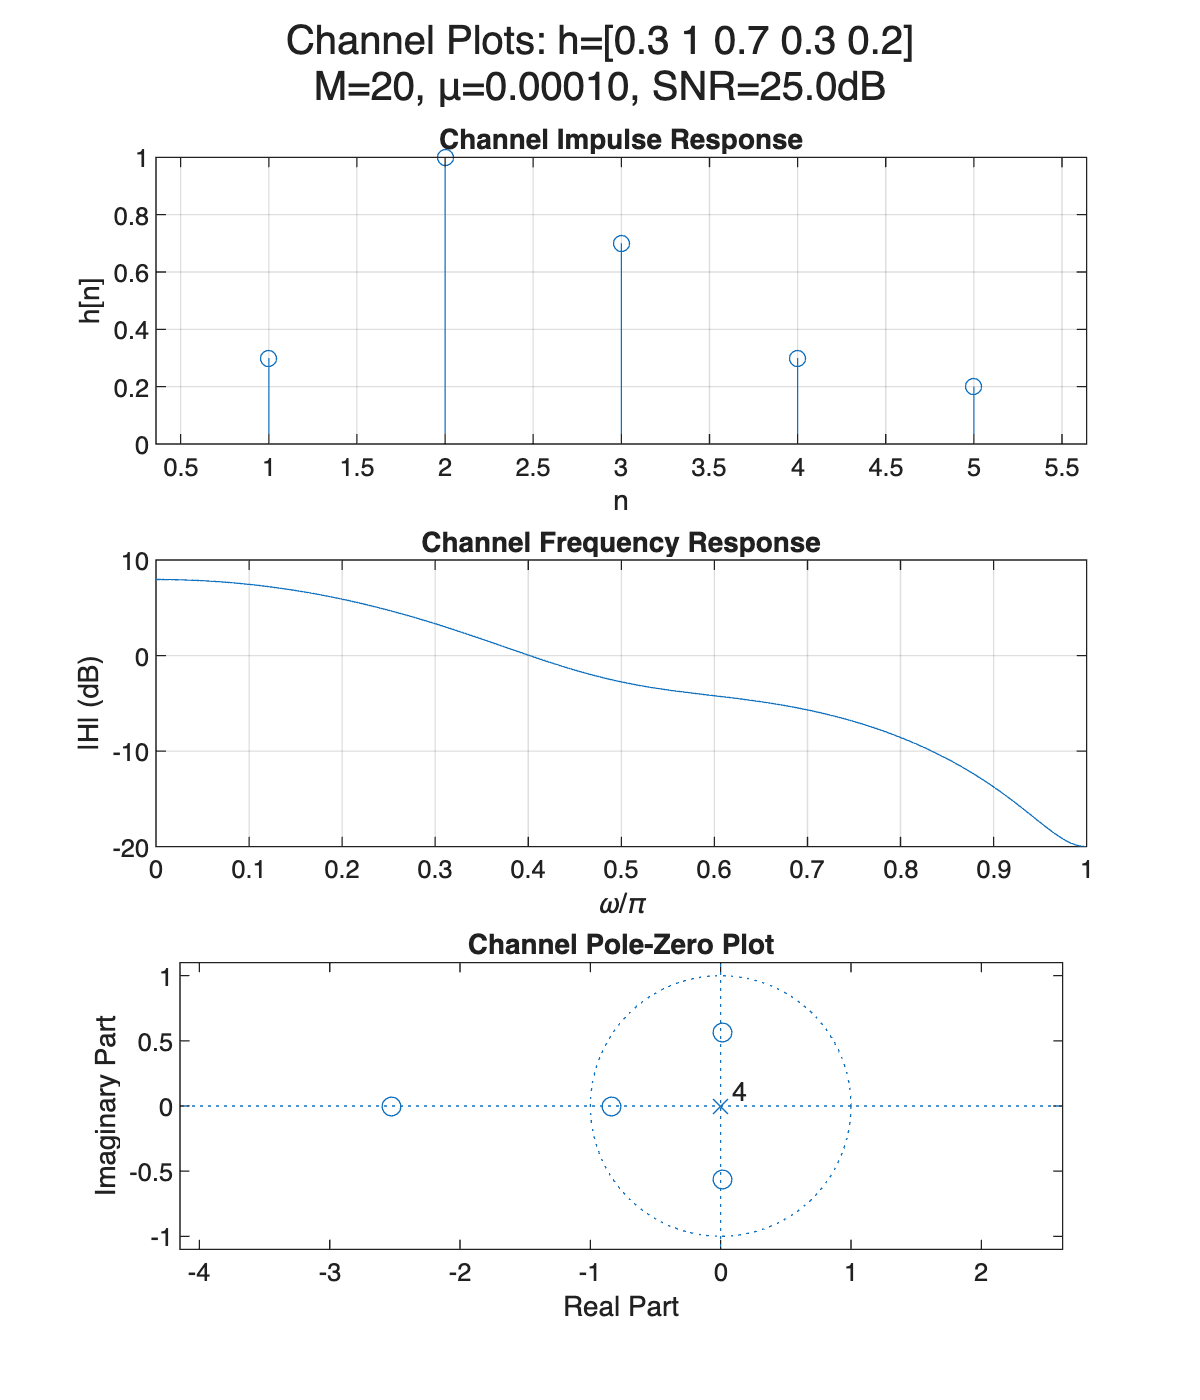

% TEST 1: basic config, same h as Part B initial
snr_db = 25;
h = [0.3, 1, 0.7, 0.3, 0.2];
mu = 0.0001;
M = 20;

plot_channel(h, snr_db, mu, M);   % reuse Part B helper

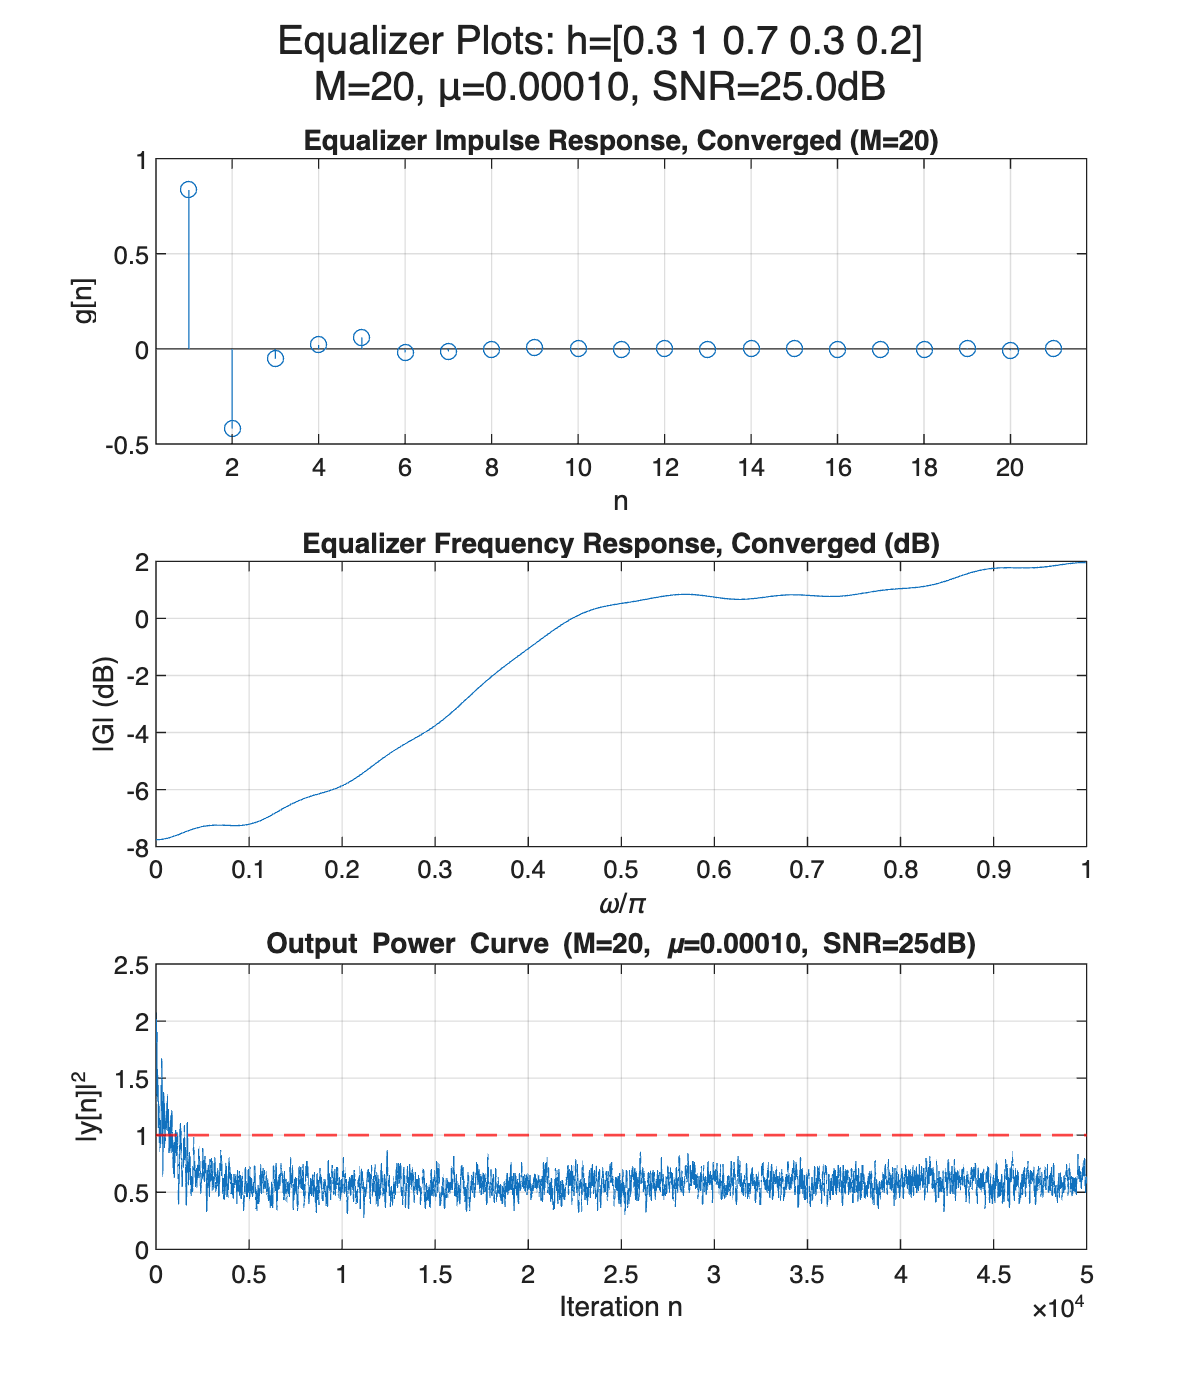


[gn_c, en_c, yn_c, xn_c, noi_power_c] = run_blind_equalizer(h, mu, M, snr_db, 50000, "impulse");

plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);   % reuse Part B helper

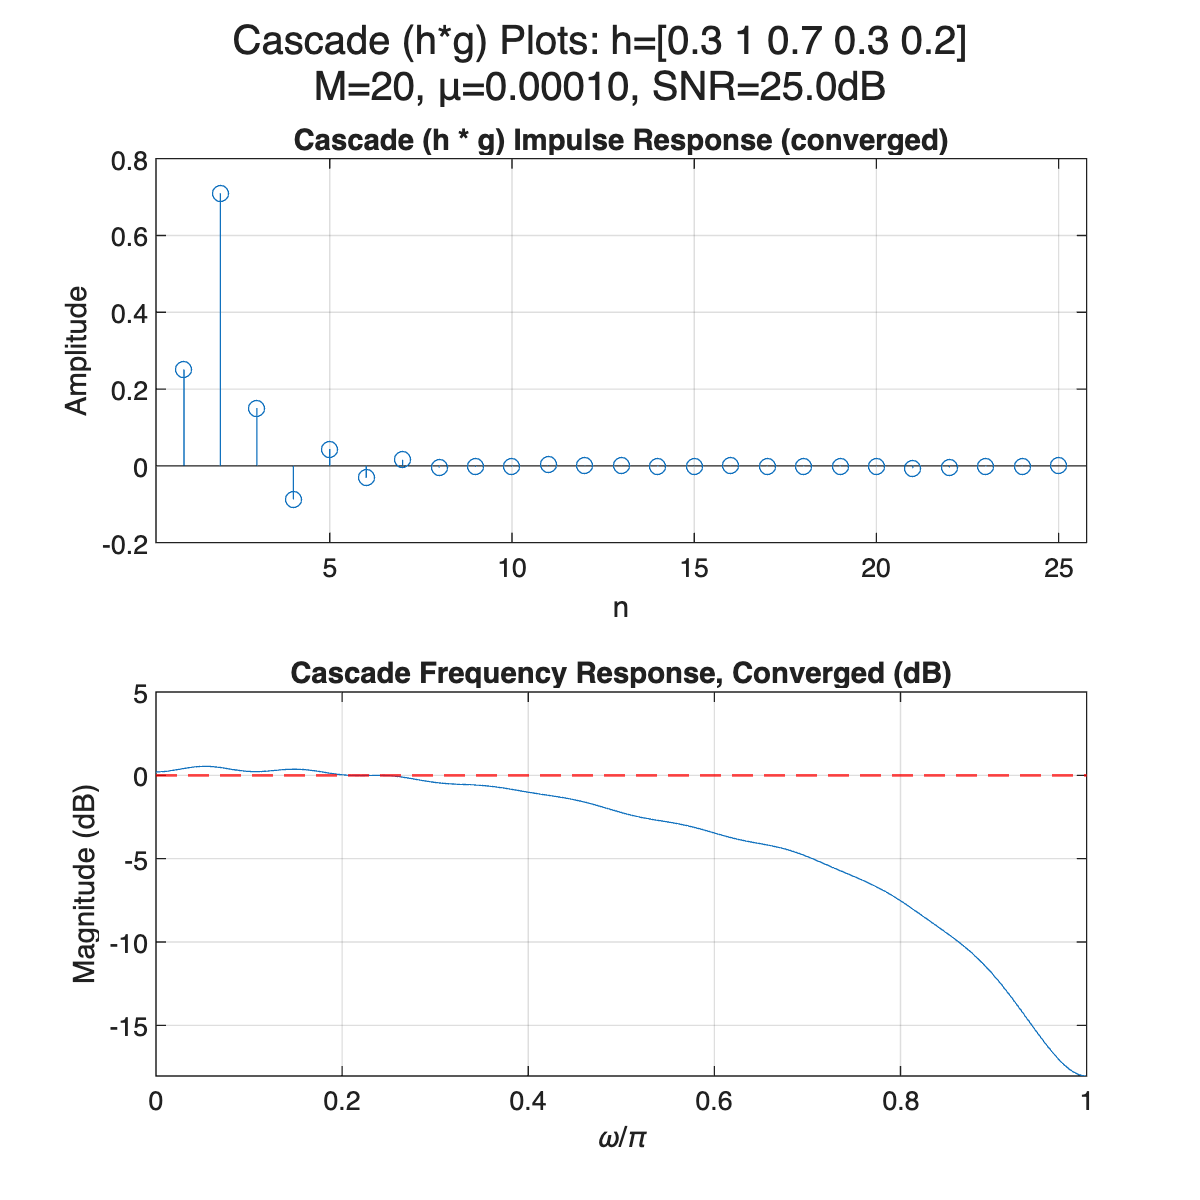

plot_cascade(h, gn_c, snr_db, mu, M);                   % reuse Part B helper

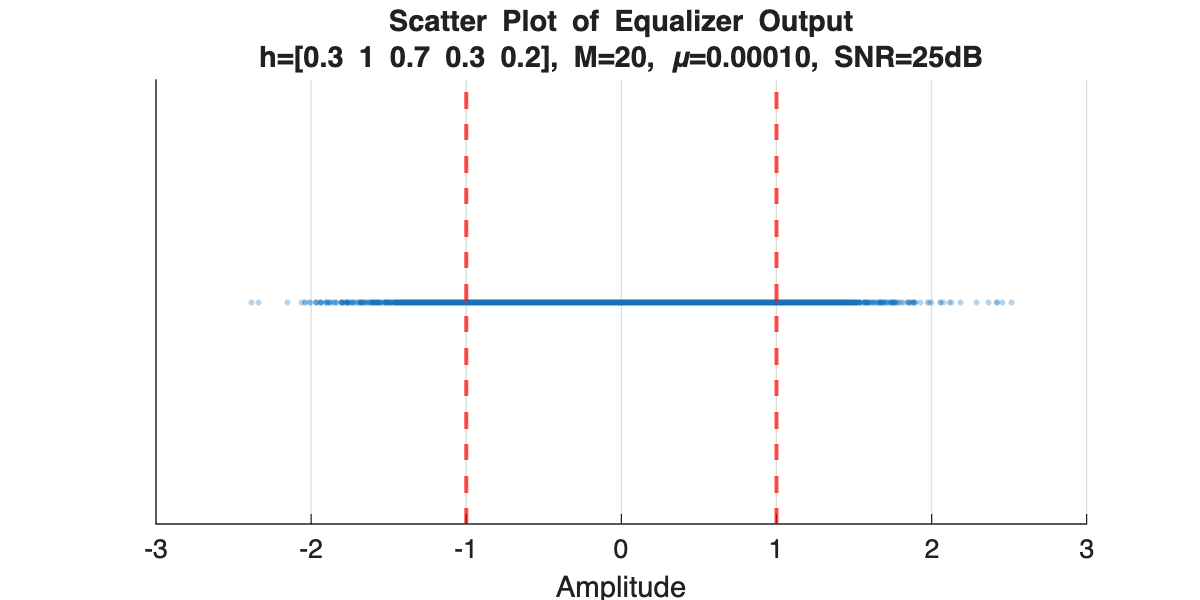

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 1 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 1 (SNR=25dB, M=20, mu=0.00010)



%output is kinda bad, try upping snr and decreasing learning rate

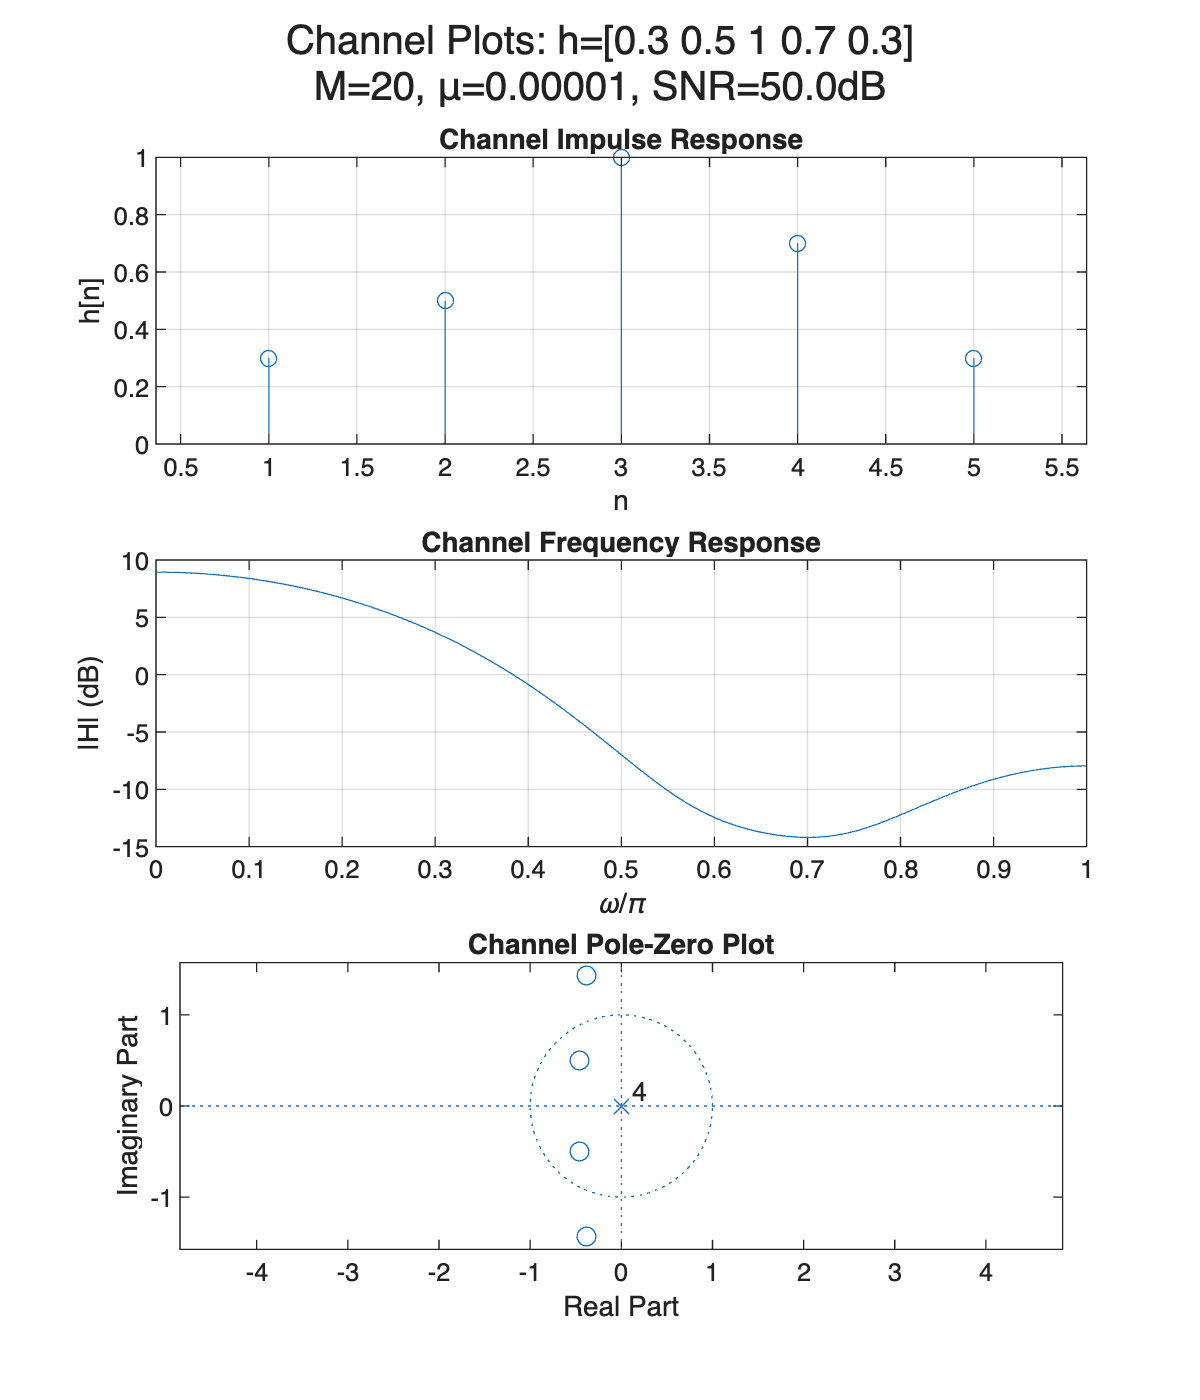

% TEST (higher snr)
snr_db = 50;
h = [0.3, 0.5, 1, 0.7, 0.3];
mu = 0.00001;
M = 20;

plot_channel(h, snr_db, mu, M);

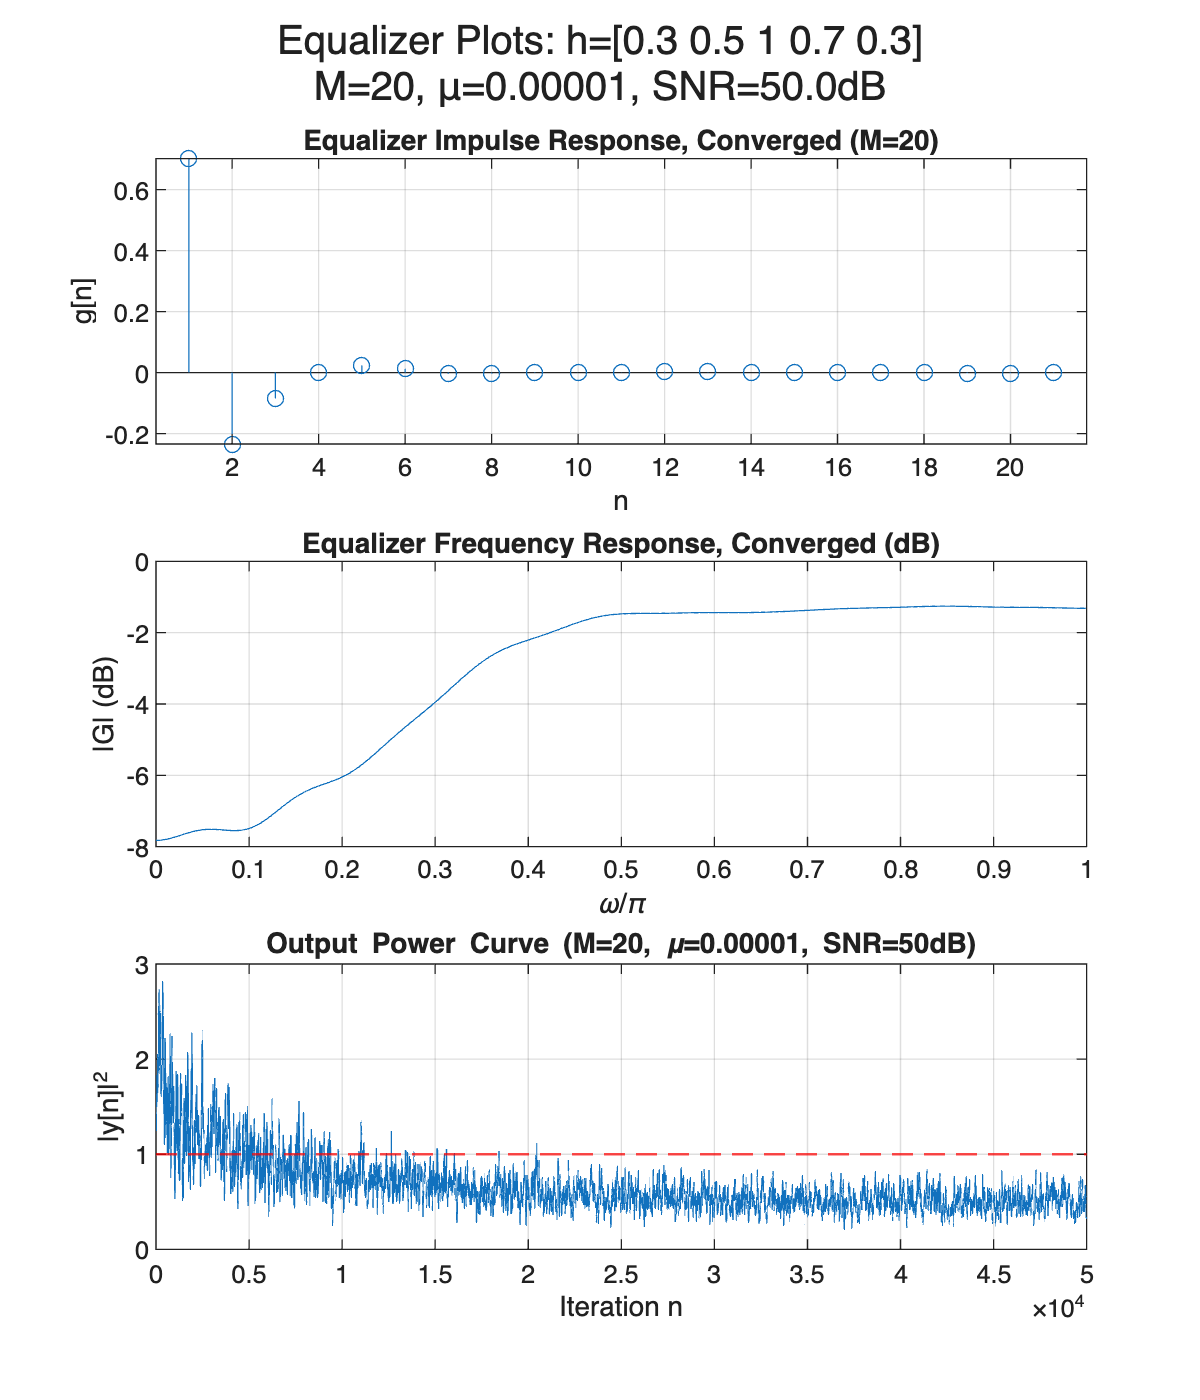


[gn_c, en_c, yn_c, xn_c, noi_power_c] = run_blind_equalizer(h, mu, M, snr_db, 50000, "impulse");

plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);

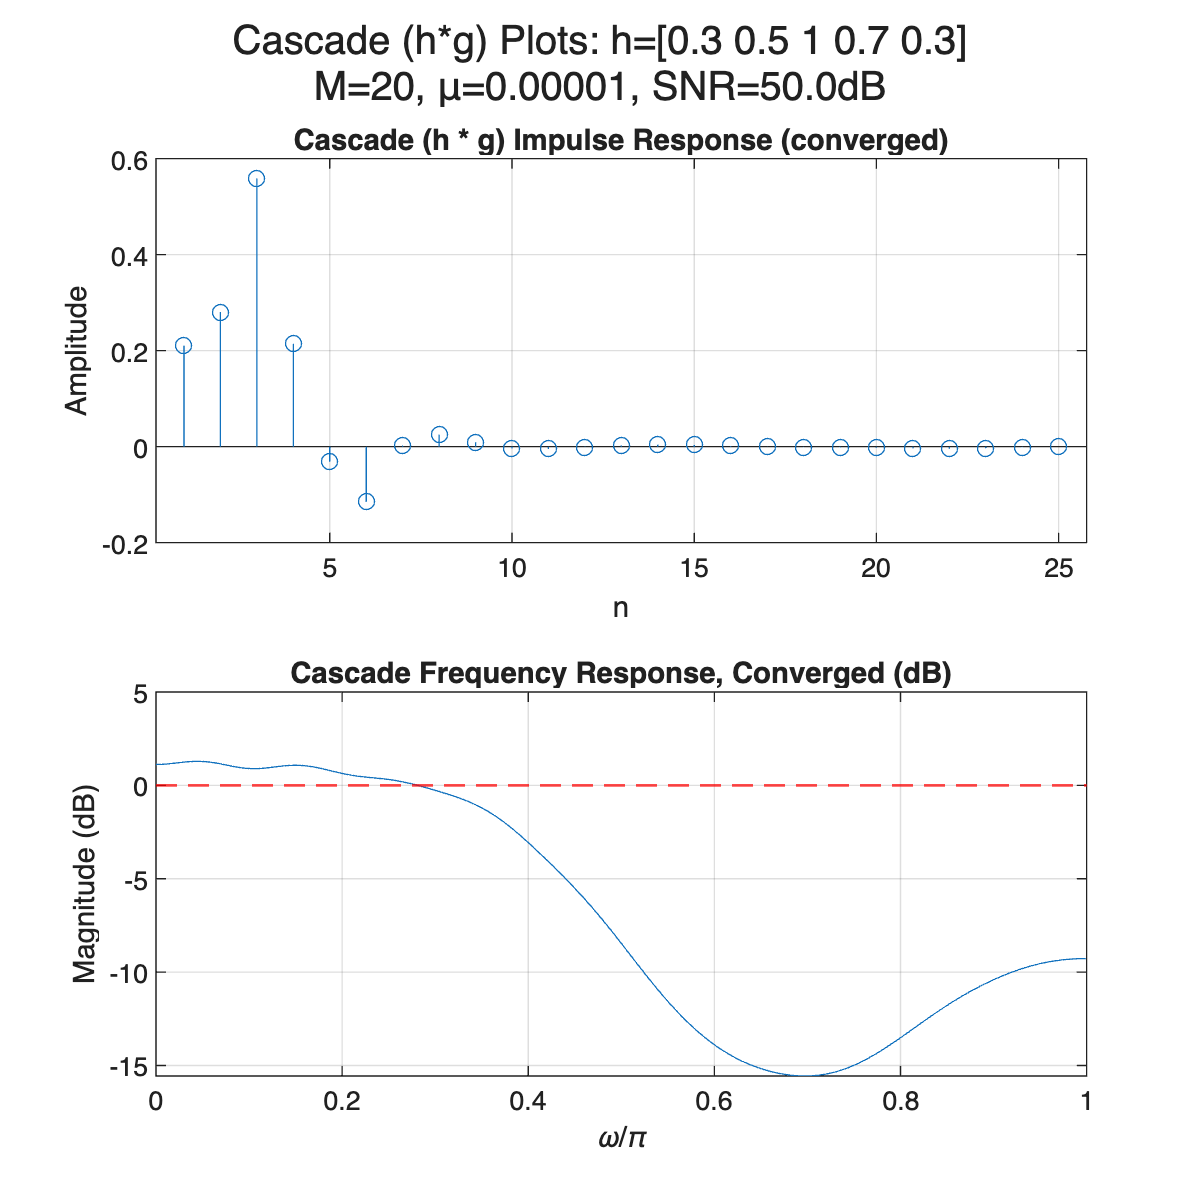

plot_cascade(h, gn_c, snr_db, mu, M);

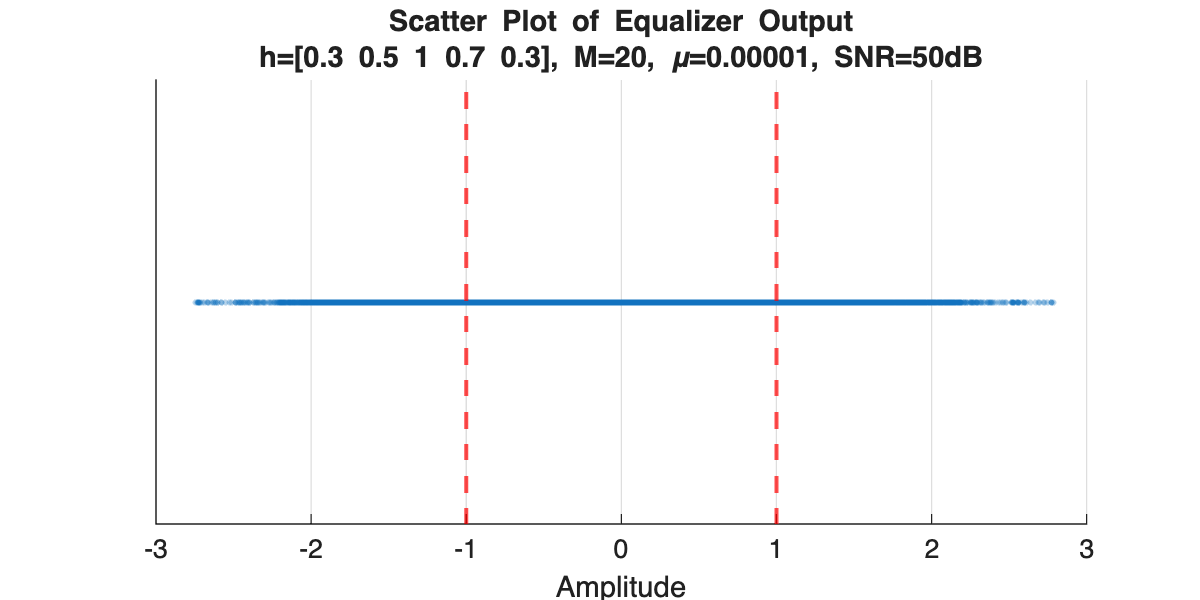

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 2 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 2 (SNR=50dB, M=20, mu=0.00001)


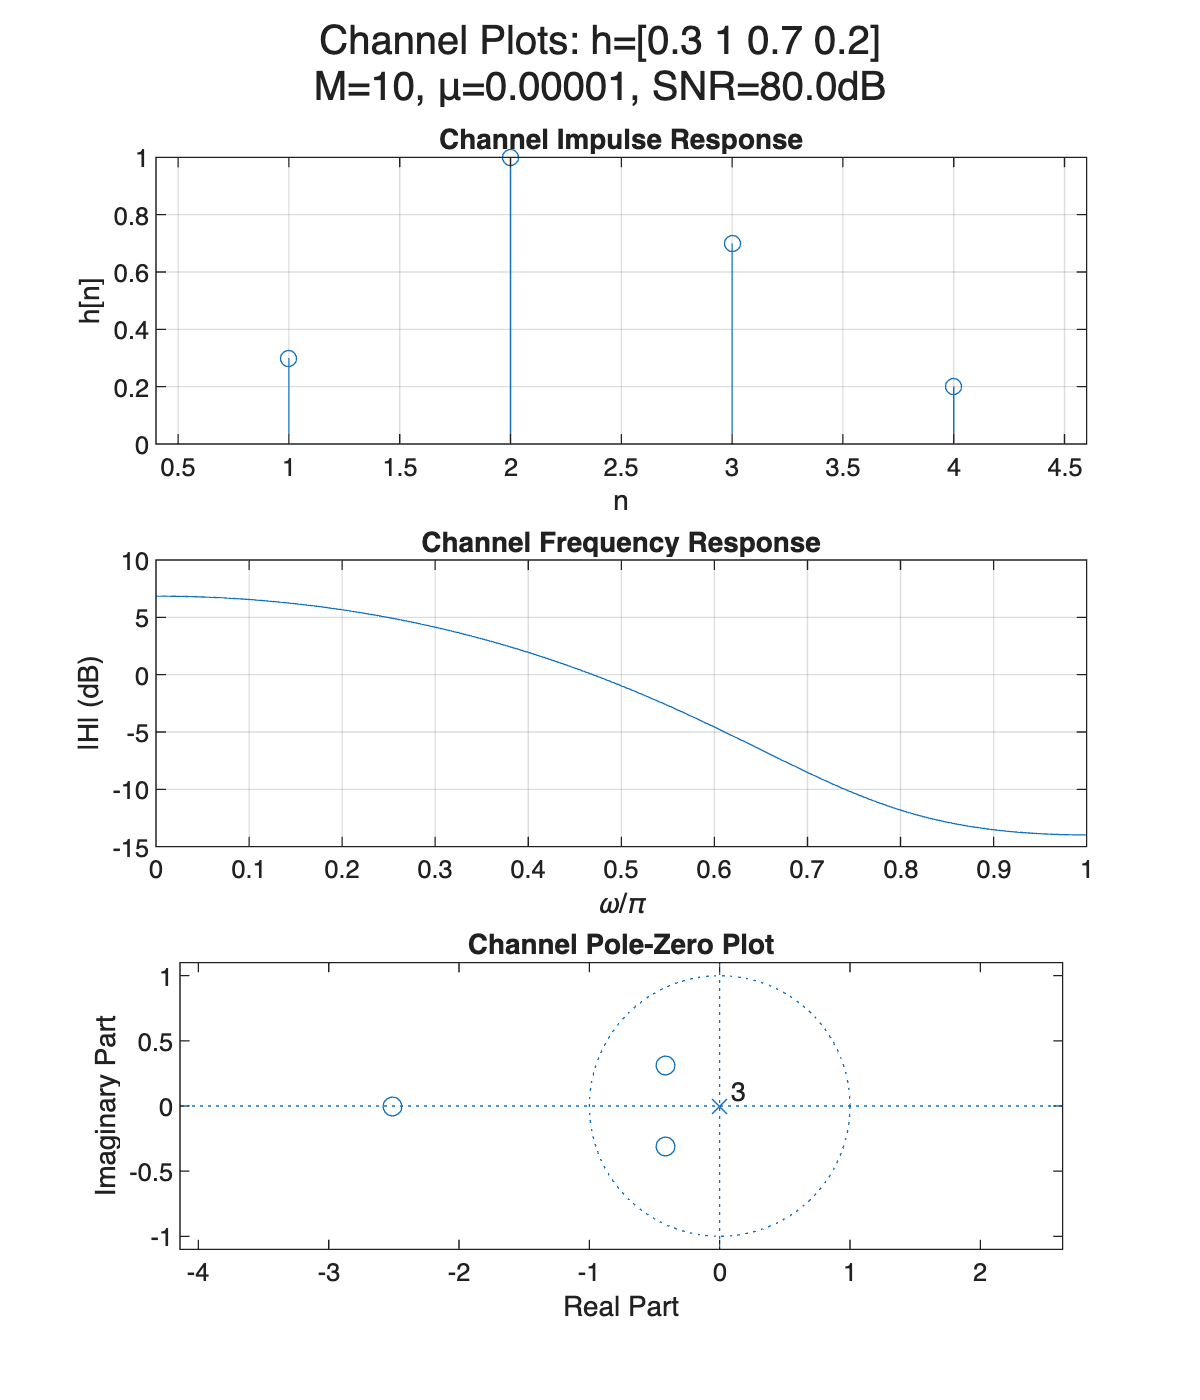

% TEST (MUCH higher snr, shorter channel, shorter filter, slower learning
snr_db = 80;
h = [0.3, 1, 0.7, 0.2];
mu = 0.00001;
M = 10;

plot_channel(h, snr_db, mu, M);

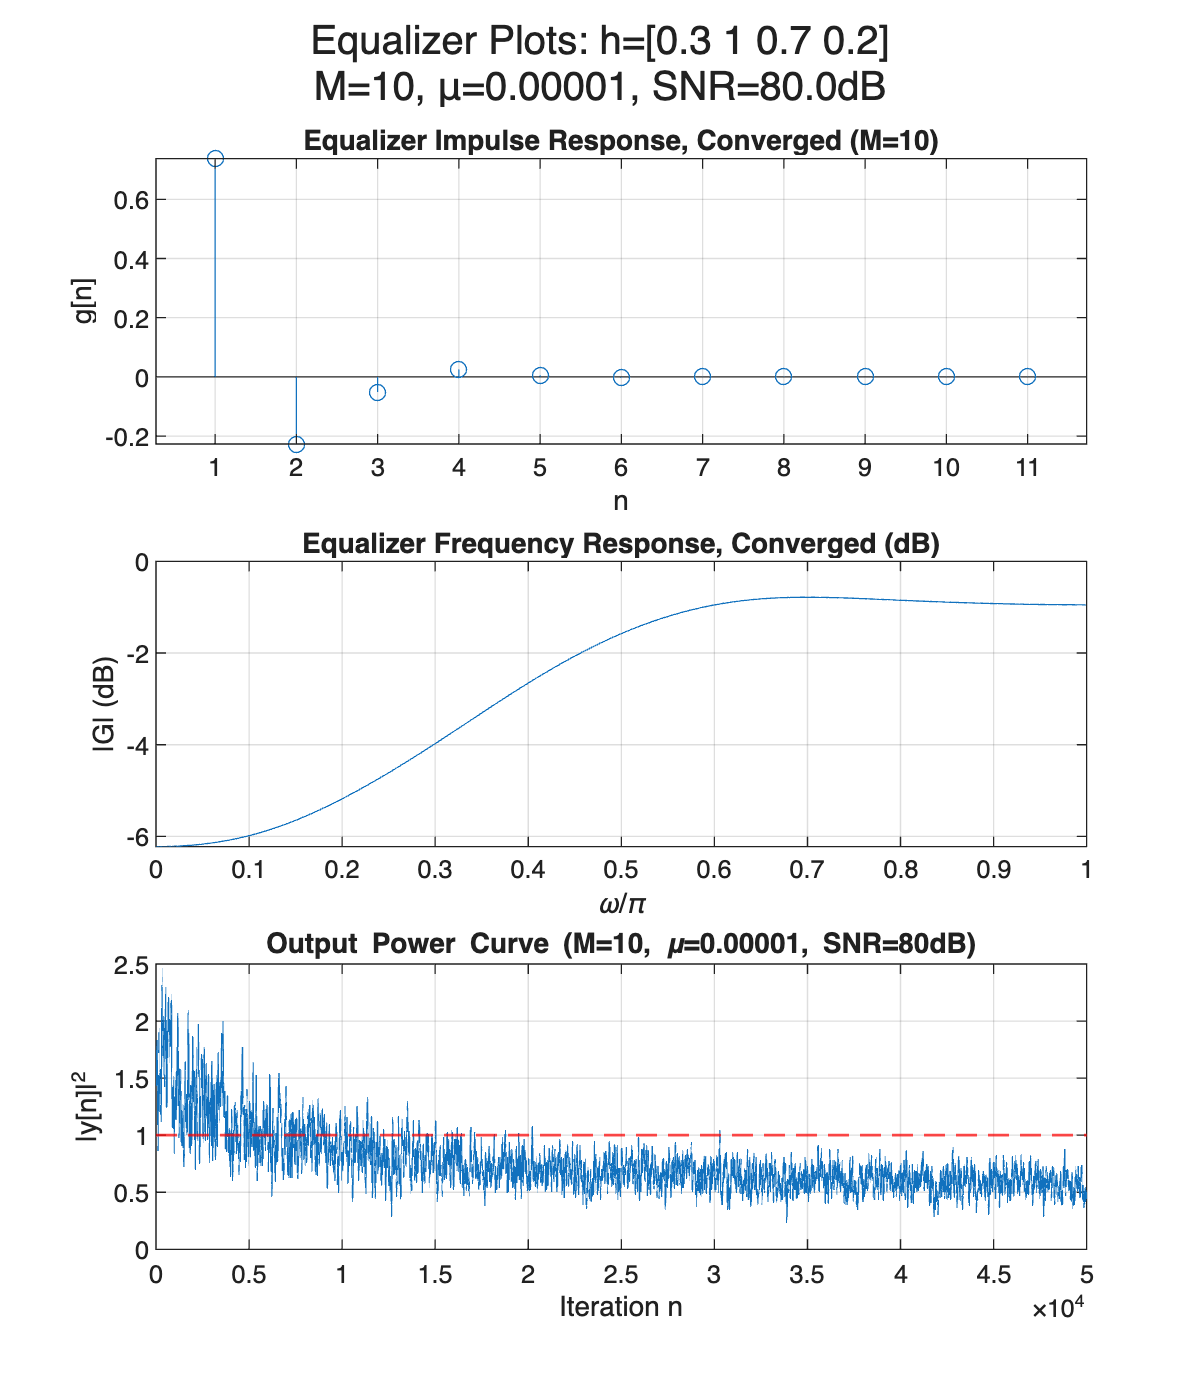


[gn_c, ~, yn_c, ~, ~] = run_blind_equalizer(h, mu, M, snr_db, 50000, "impulse");

plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);

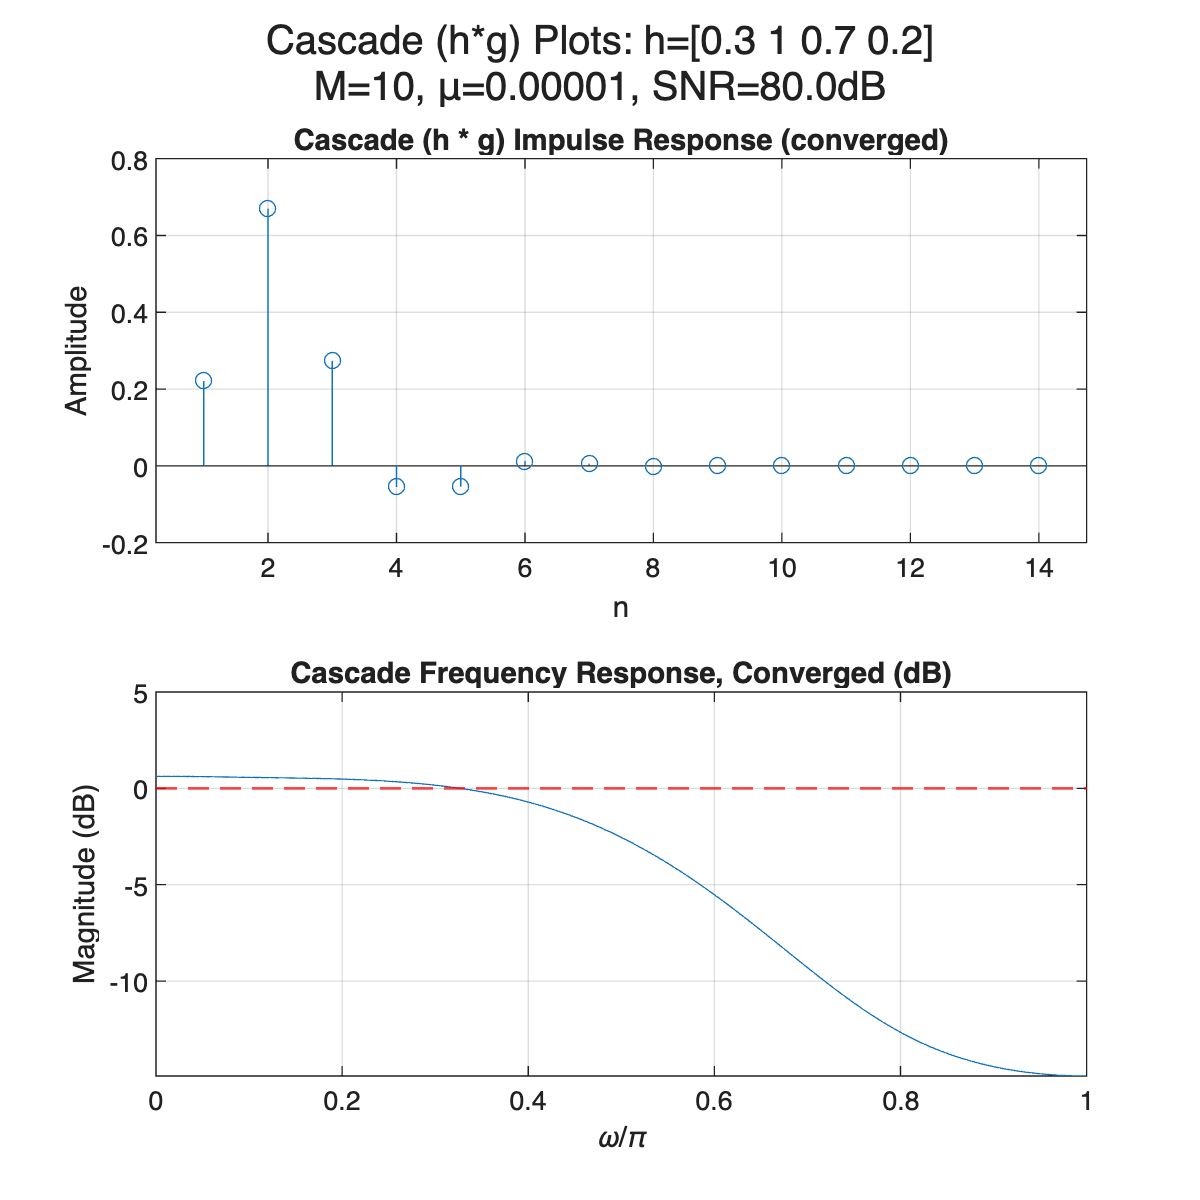

plot_cascade(h, gn_c, snr_db, mu, M);

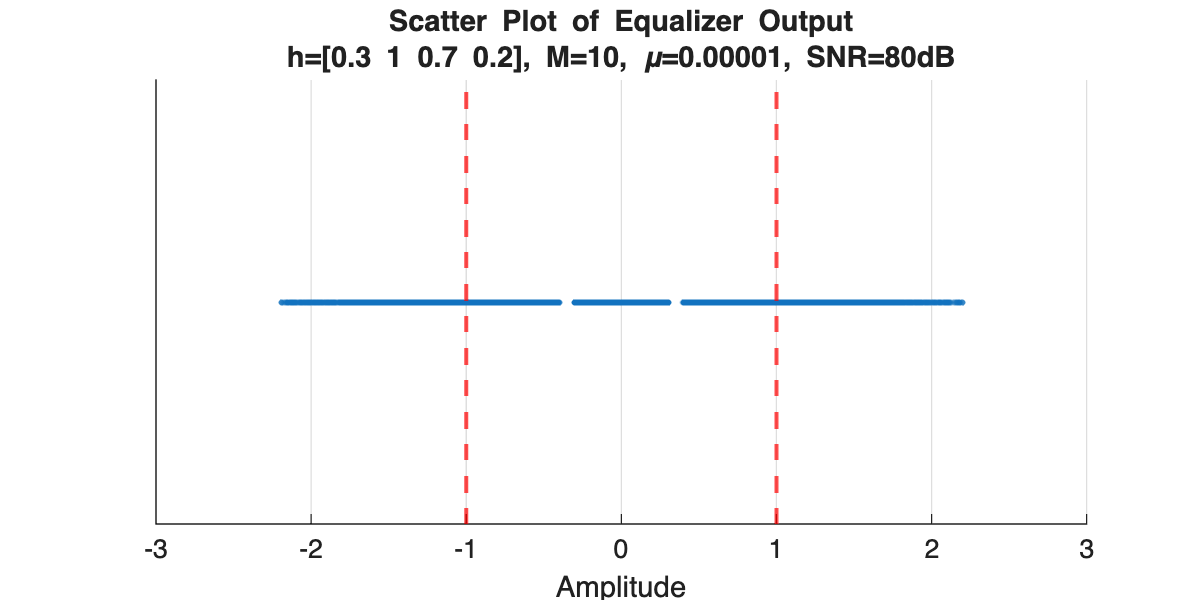

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 3 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 3 (SNR=80dB, M=10, mu=0.00001)


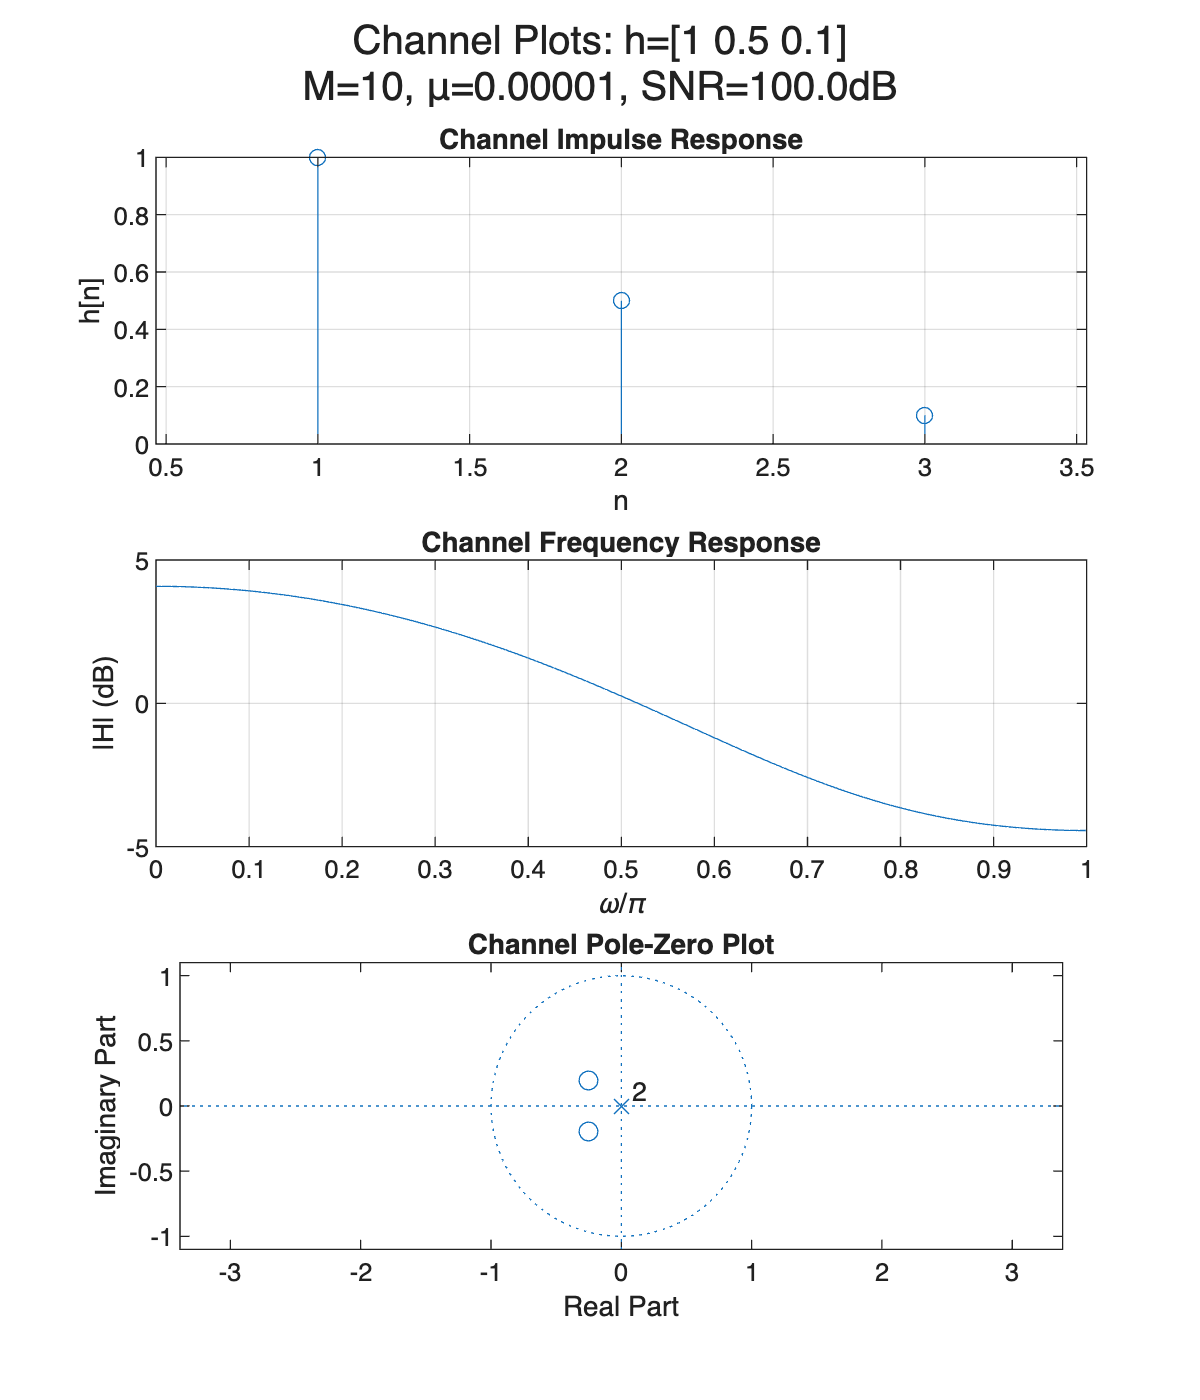

% TEST (min phase channel, larger mu)
snr_db = 100;
h = [1, 0.5, 0.1];   % MIN PHASE
mu = 0.00001;
M = 10;

plot_channel(h, snr_db, mu, M);


[gn_c, ~, yn_c, ~, ~] = run_blind_equalizer(h, mu, M, snr_db, 100000, "centered impulse");

gn =      0     0     0     0     1     0     0     0     0     0     0


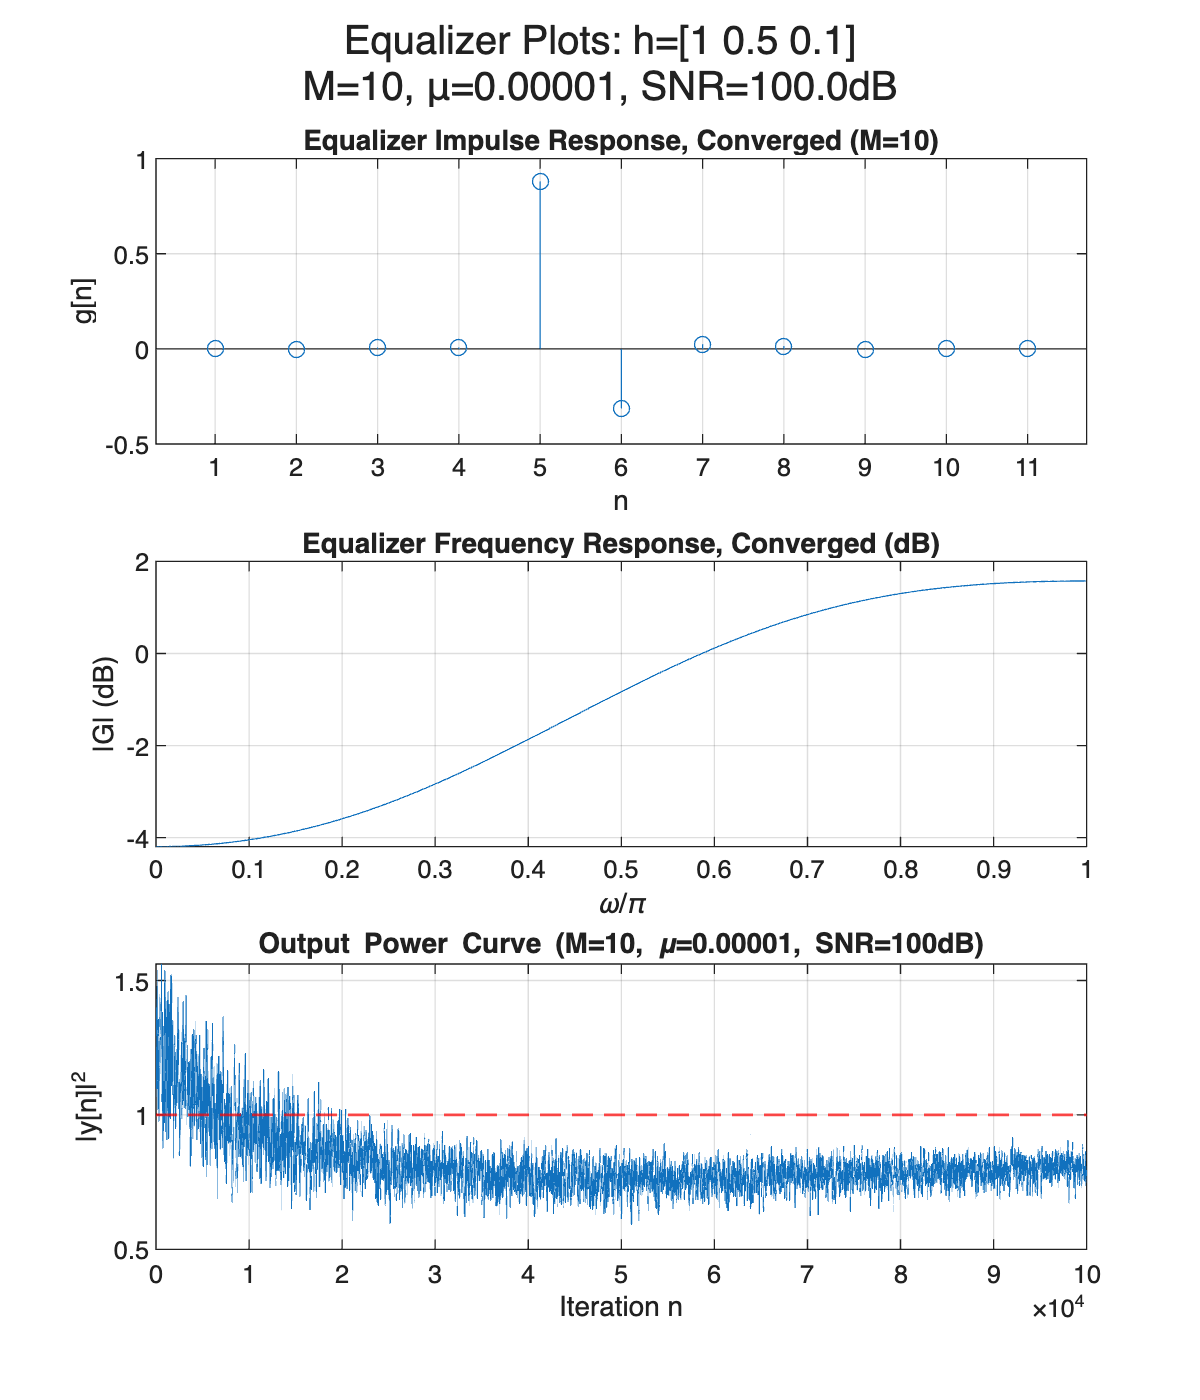


plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);

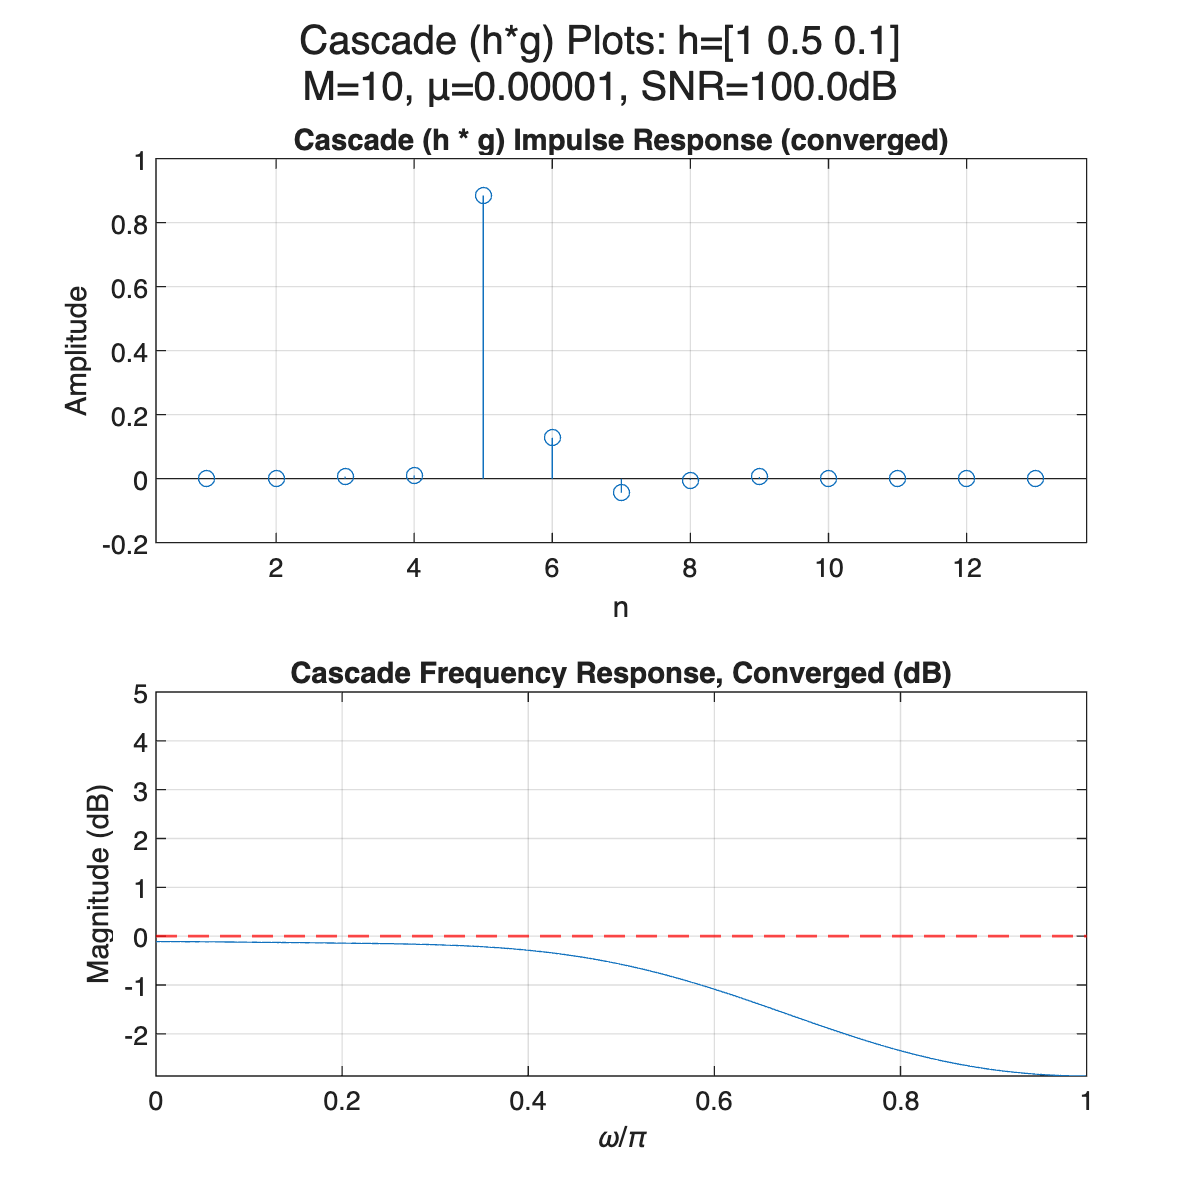

plot_cascade(h, gn_c, snr_db, mu, M);

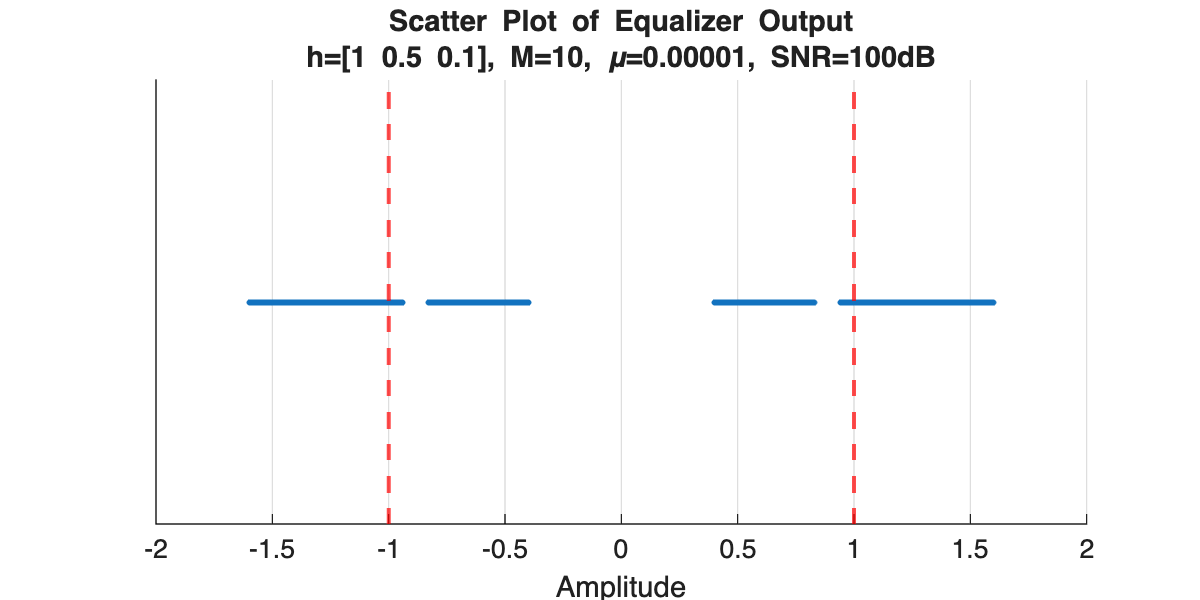

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 4 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 4 (SNR=100dB, M=10, mu=0.00001)



% power is TOO low from this, even tho scatter looks better

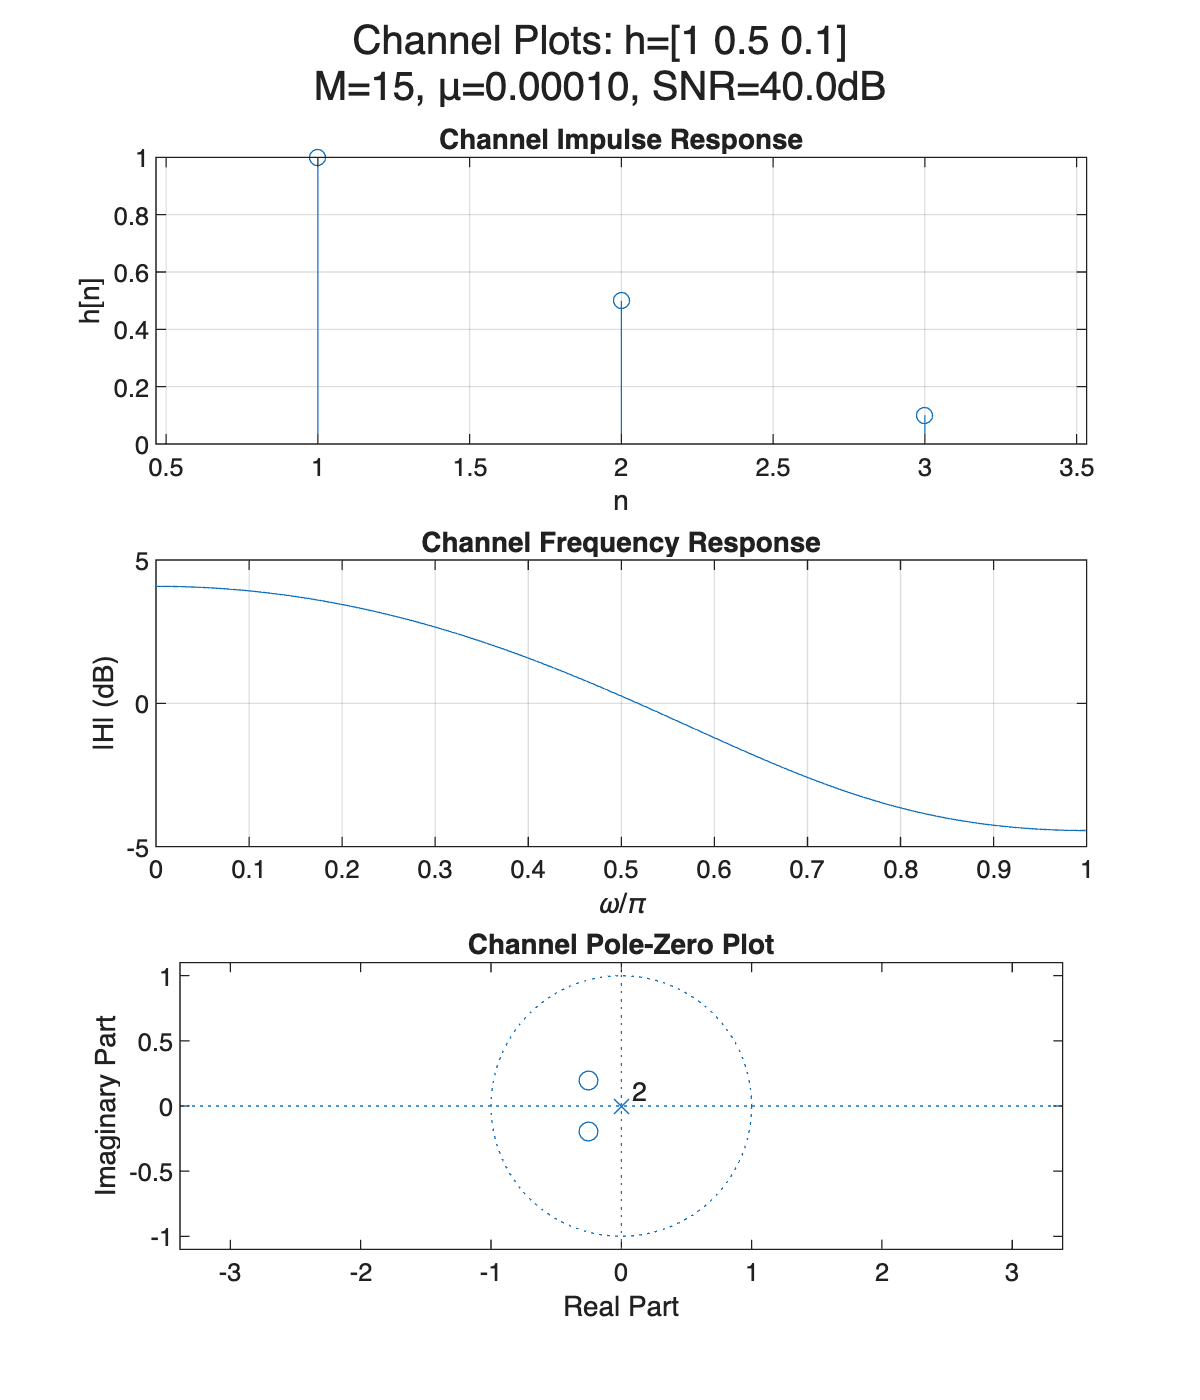

% TEST (min phase channel, larger mu)
snr_db = 40;
h = [1, 0.5, 0.1];   % MIN PHASE
mu = 0.0001;
M = 15;

plot_channel(h, snr_db, mu, M);

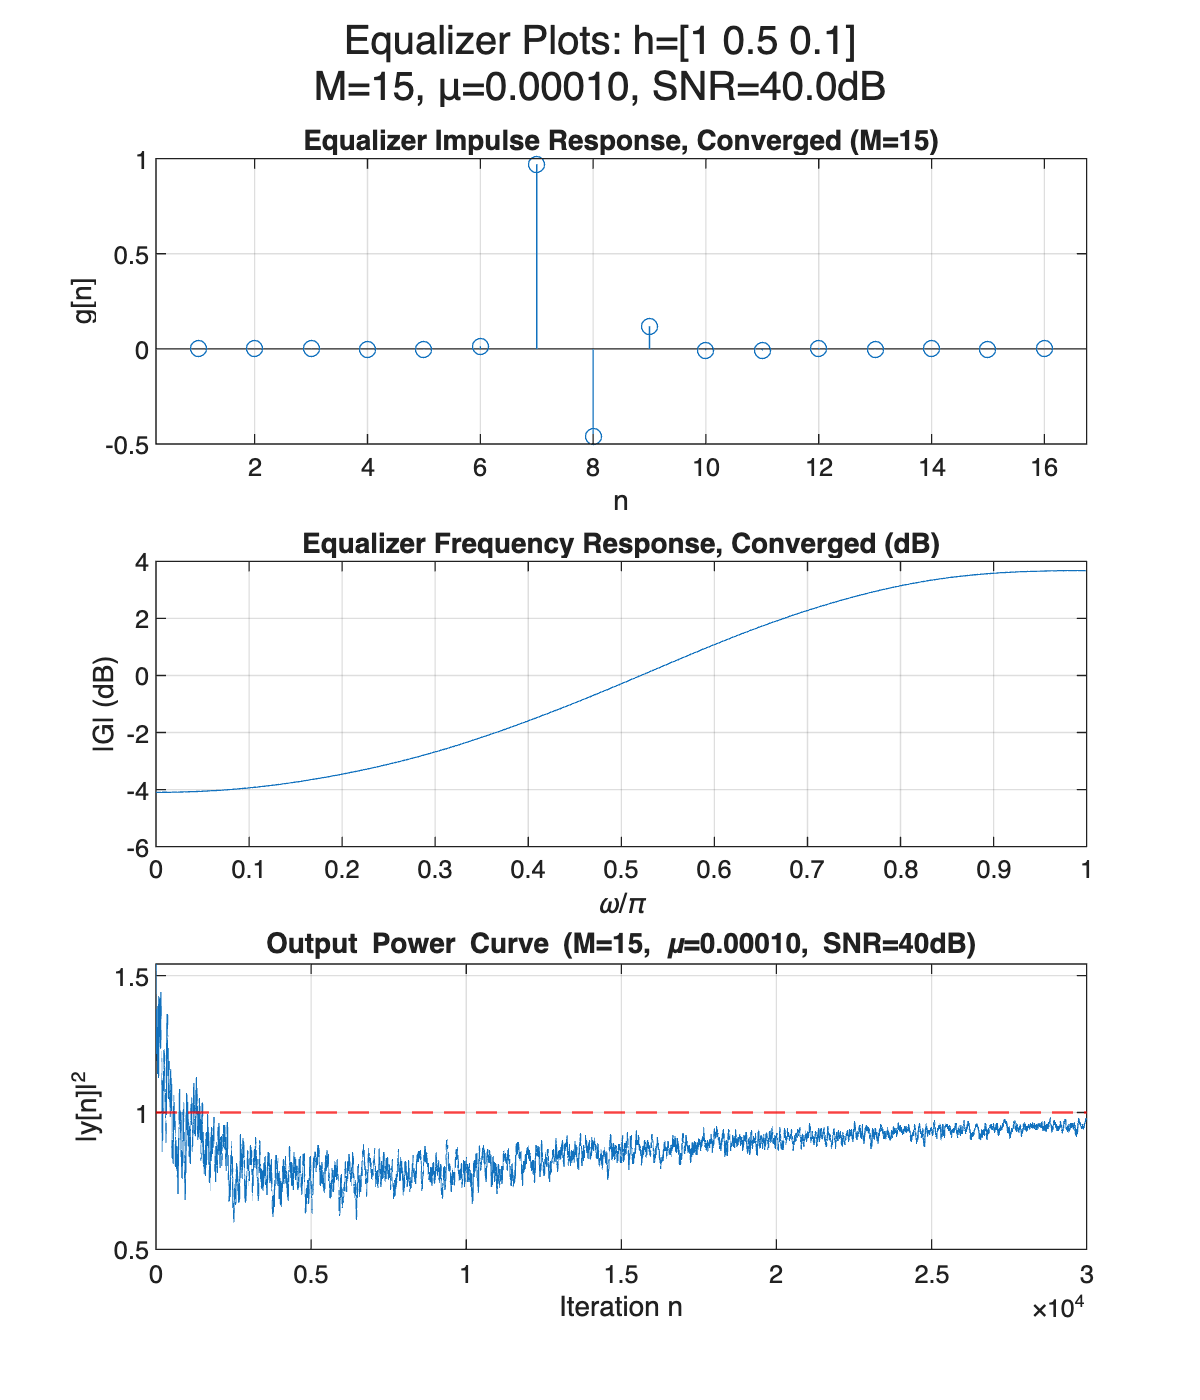


[gn_c, ~, yn_c, ~, ~] = run_blind_equalizer(h, mu, M, snr_db, 30000, "centered impulse");

plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);

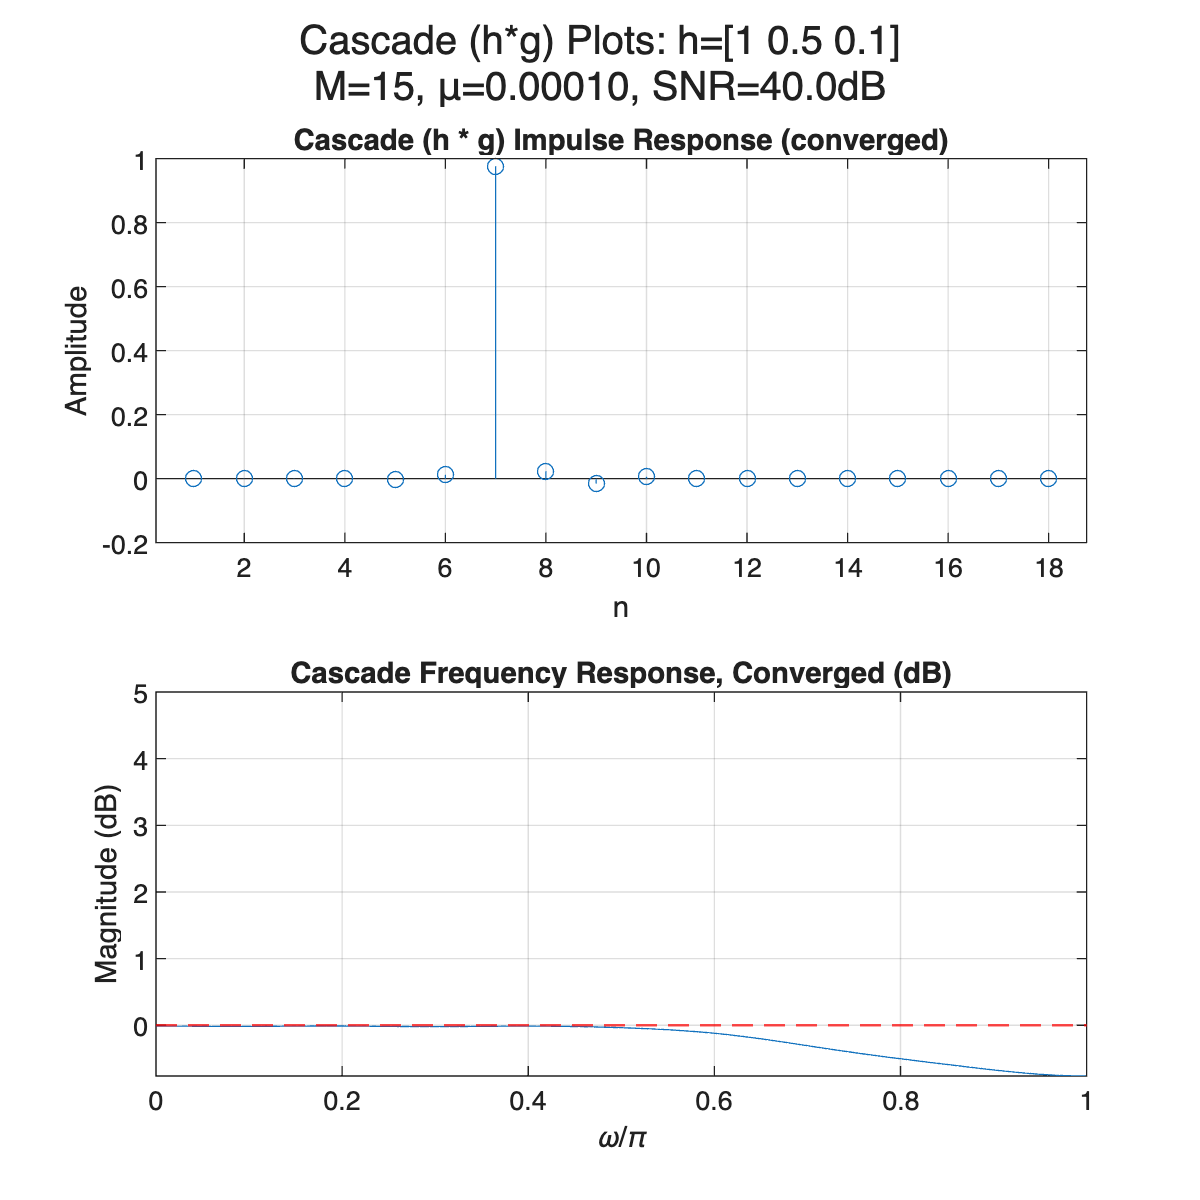

plot_cascade(h, gn_c, snr_db, mu, M);

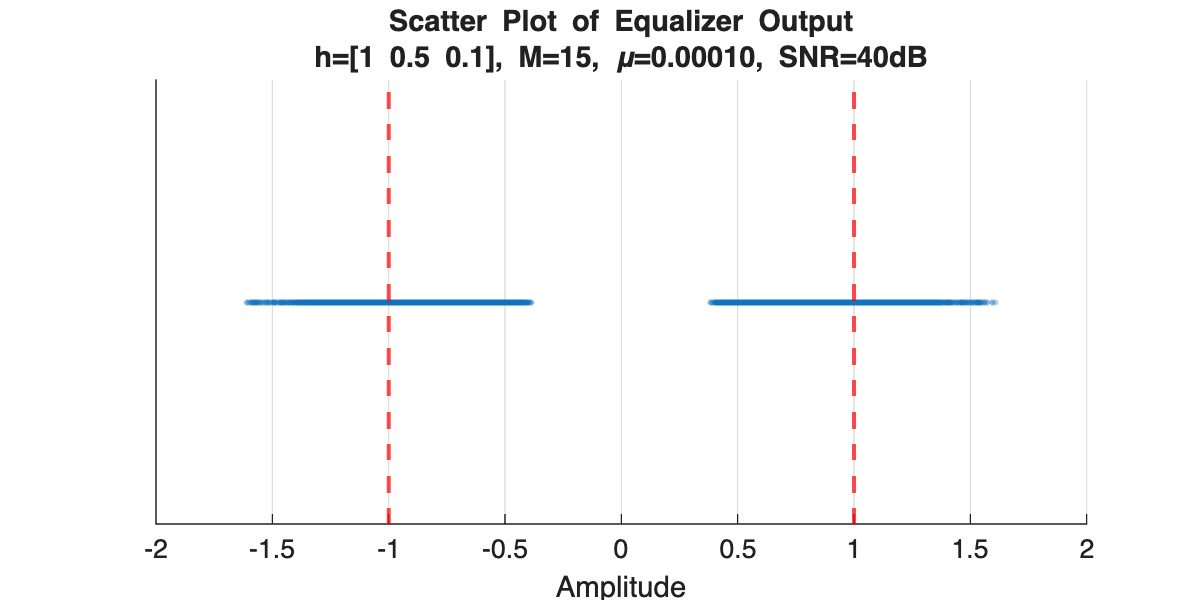

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 5 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 5 (SNR=40dB, M=15, mu=0.00010)


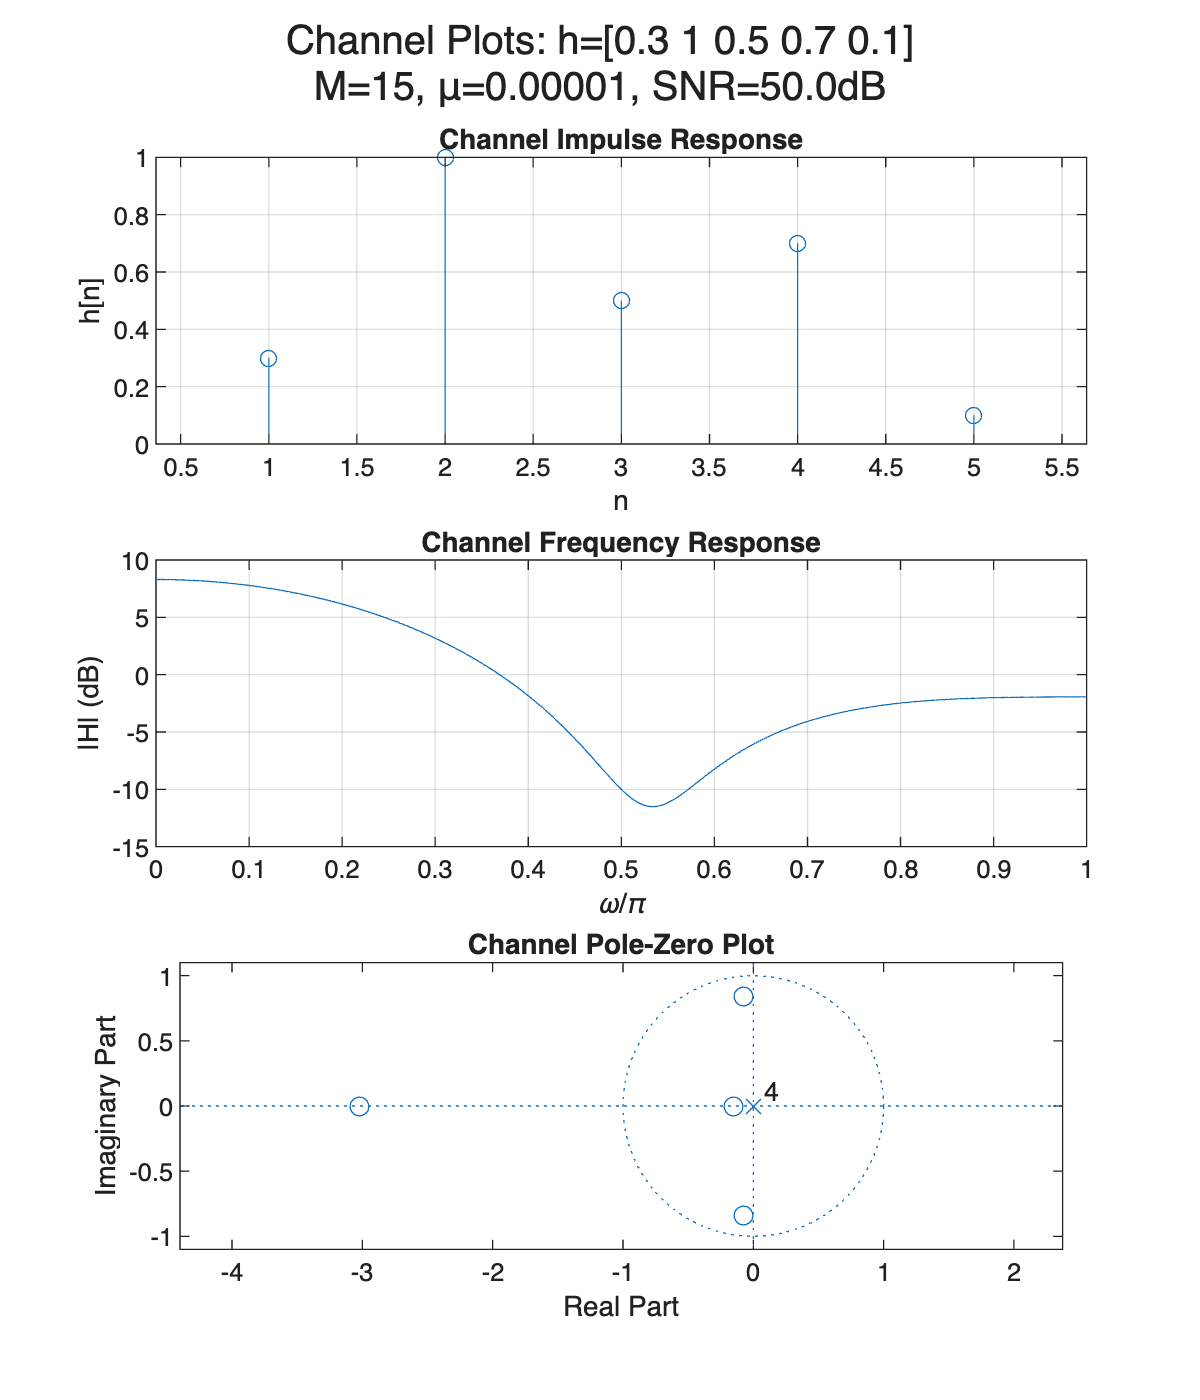

% TEST 
snr_db = 50;
h = [0.3, 1, 0.5, 0.7, 0.1];  
mu = 0.00001;
M = 15;

plot_channel(h, snr_db, mu, M);

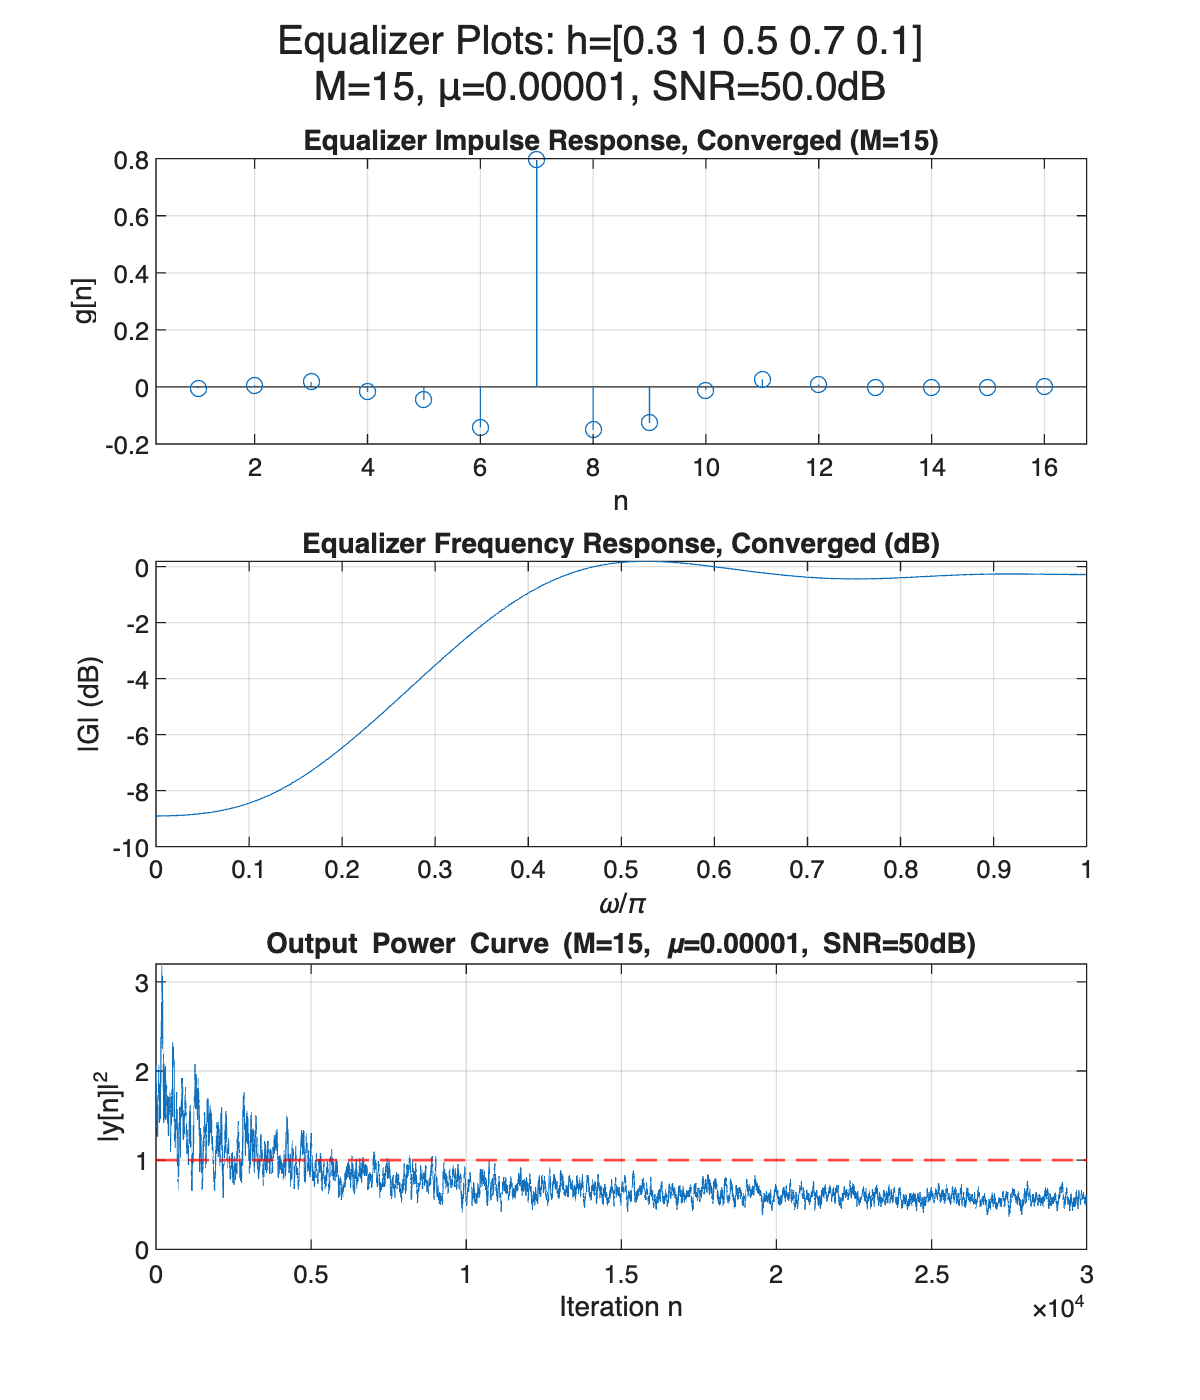


[gn_c, ~, yn_c, ~, ~] = run_blind_equalizer(h, mu, M, snr_db, 30000, "centered impulse");

plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);

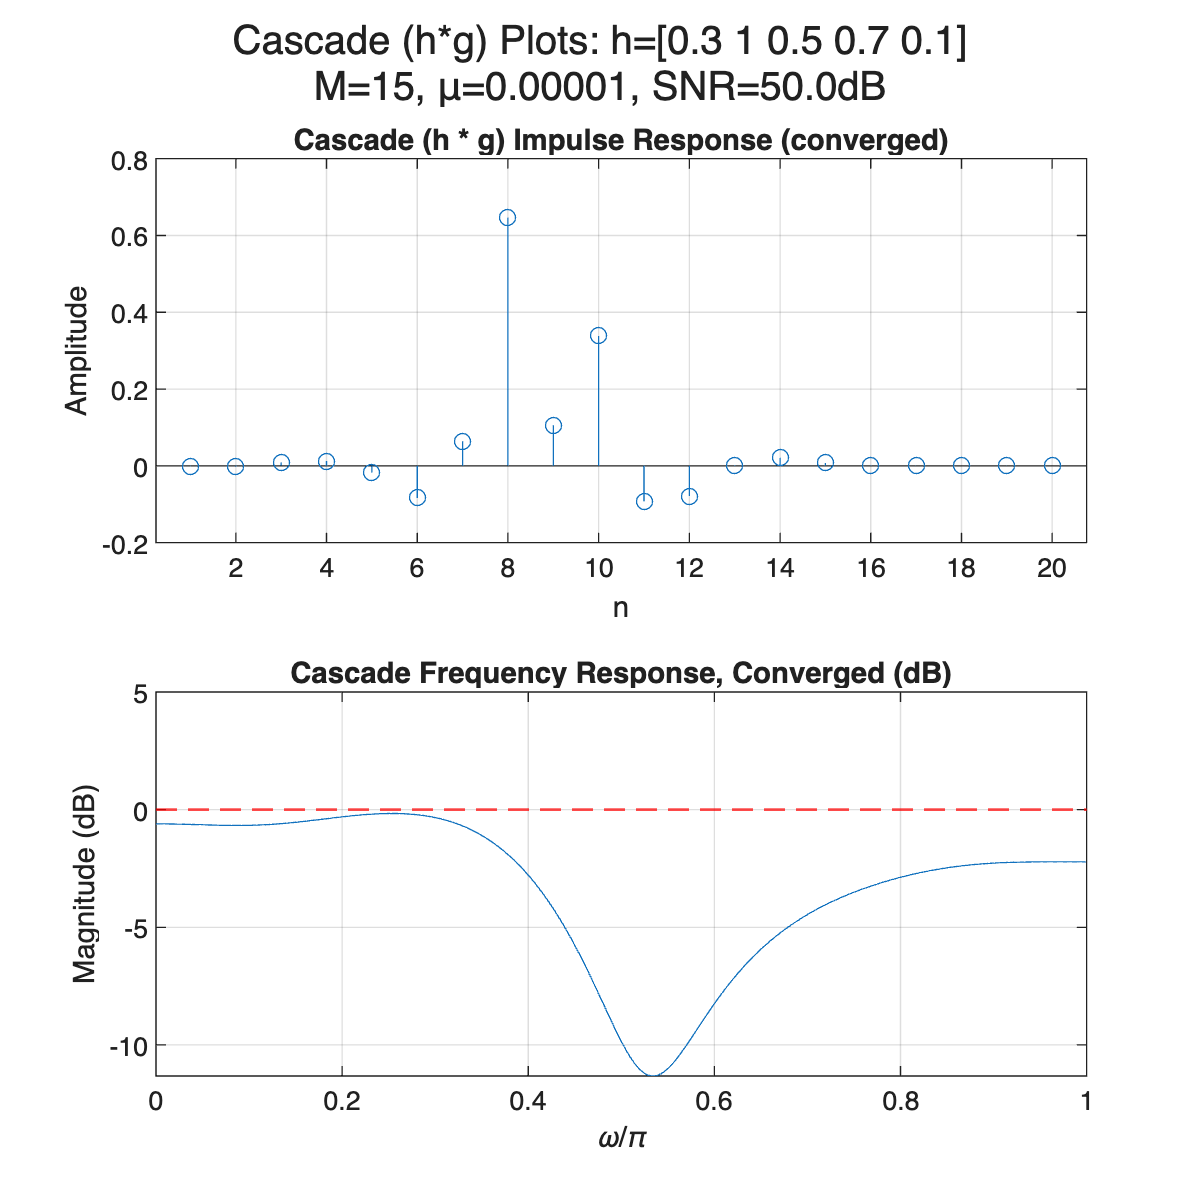

plot_cascade(h, gn_c, snr_db, mu, M);

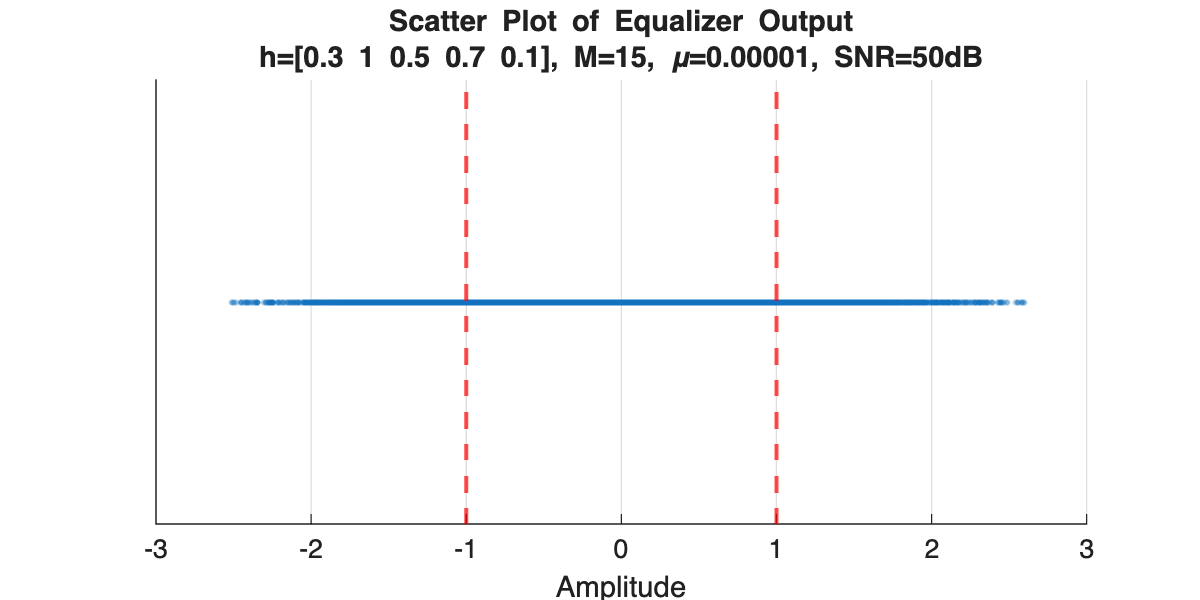

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 6 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 6 (SNR=50dB, M=15, mu=0.00001)


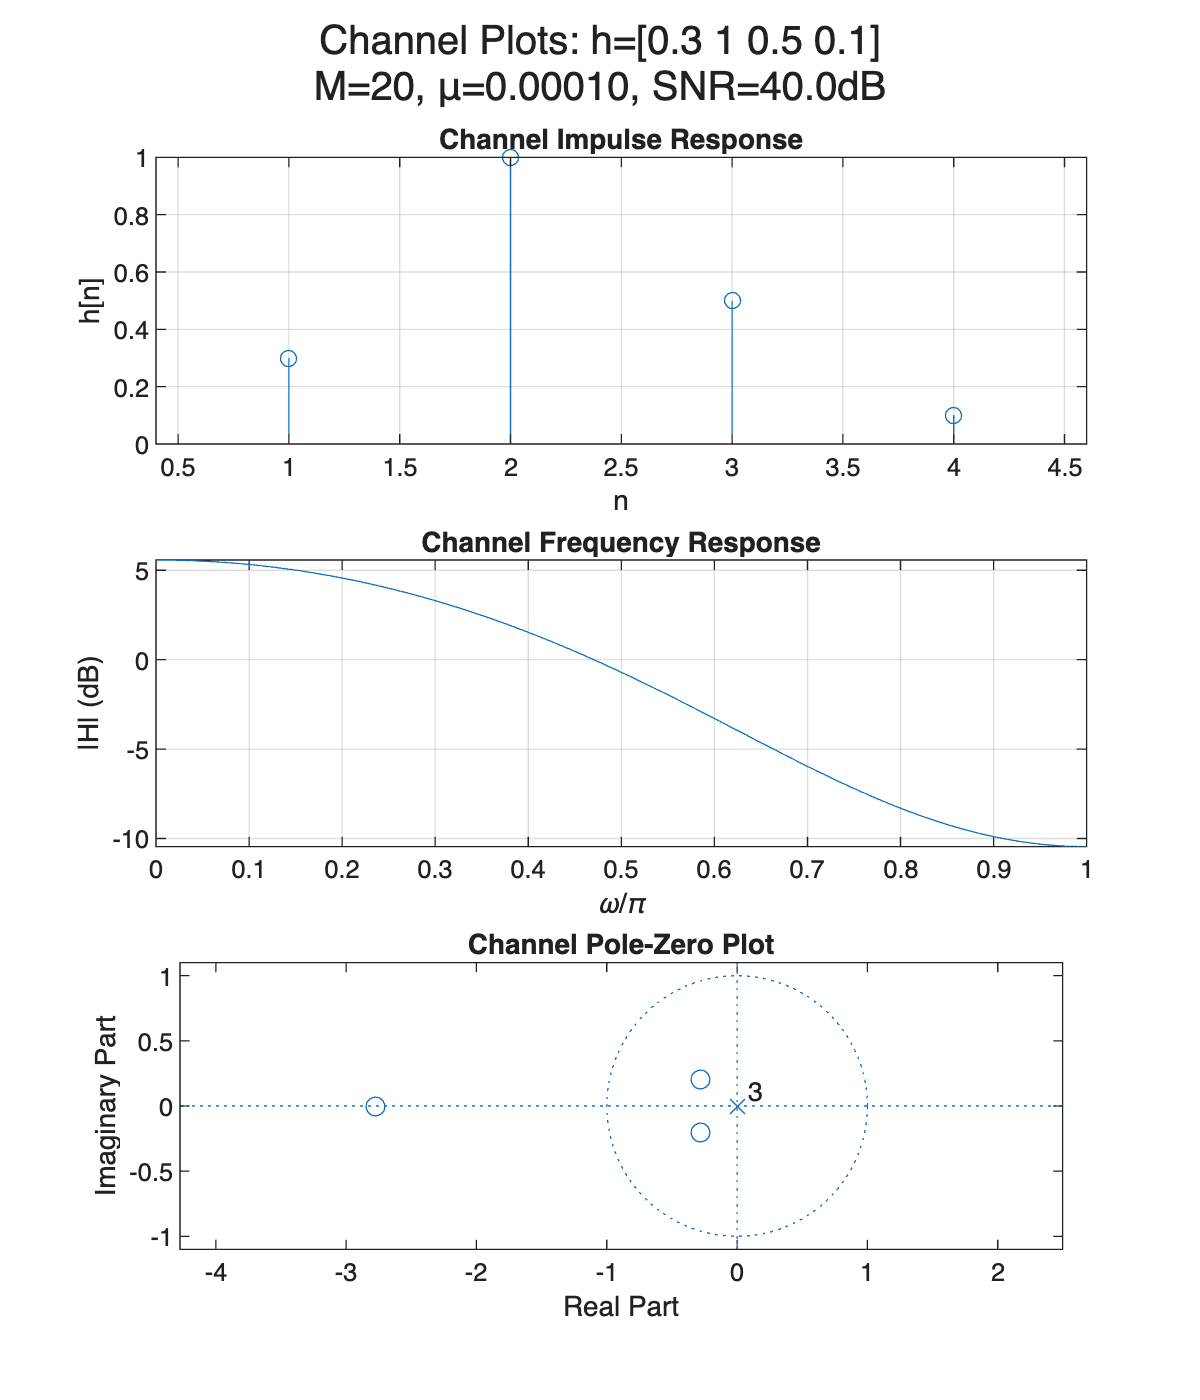

% TEST 
snr_db = 40;
h = [0.3, 1, 0.5, 0.1];
mu = 0.0001;
M = 20;

plot_channel(h, snr_db, mu, M);

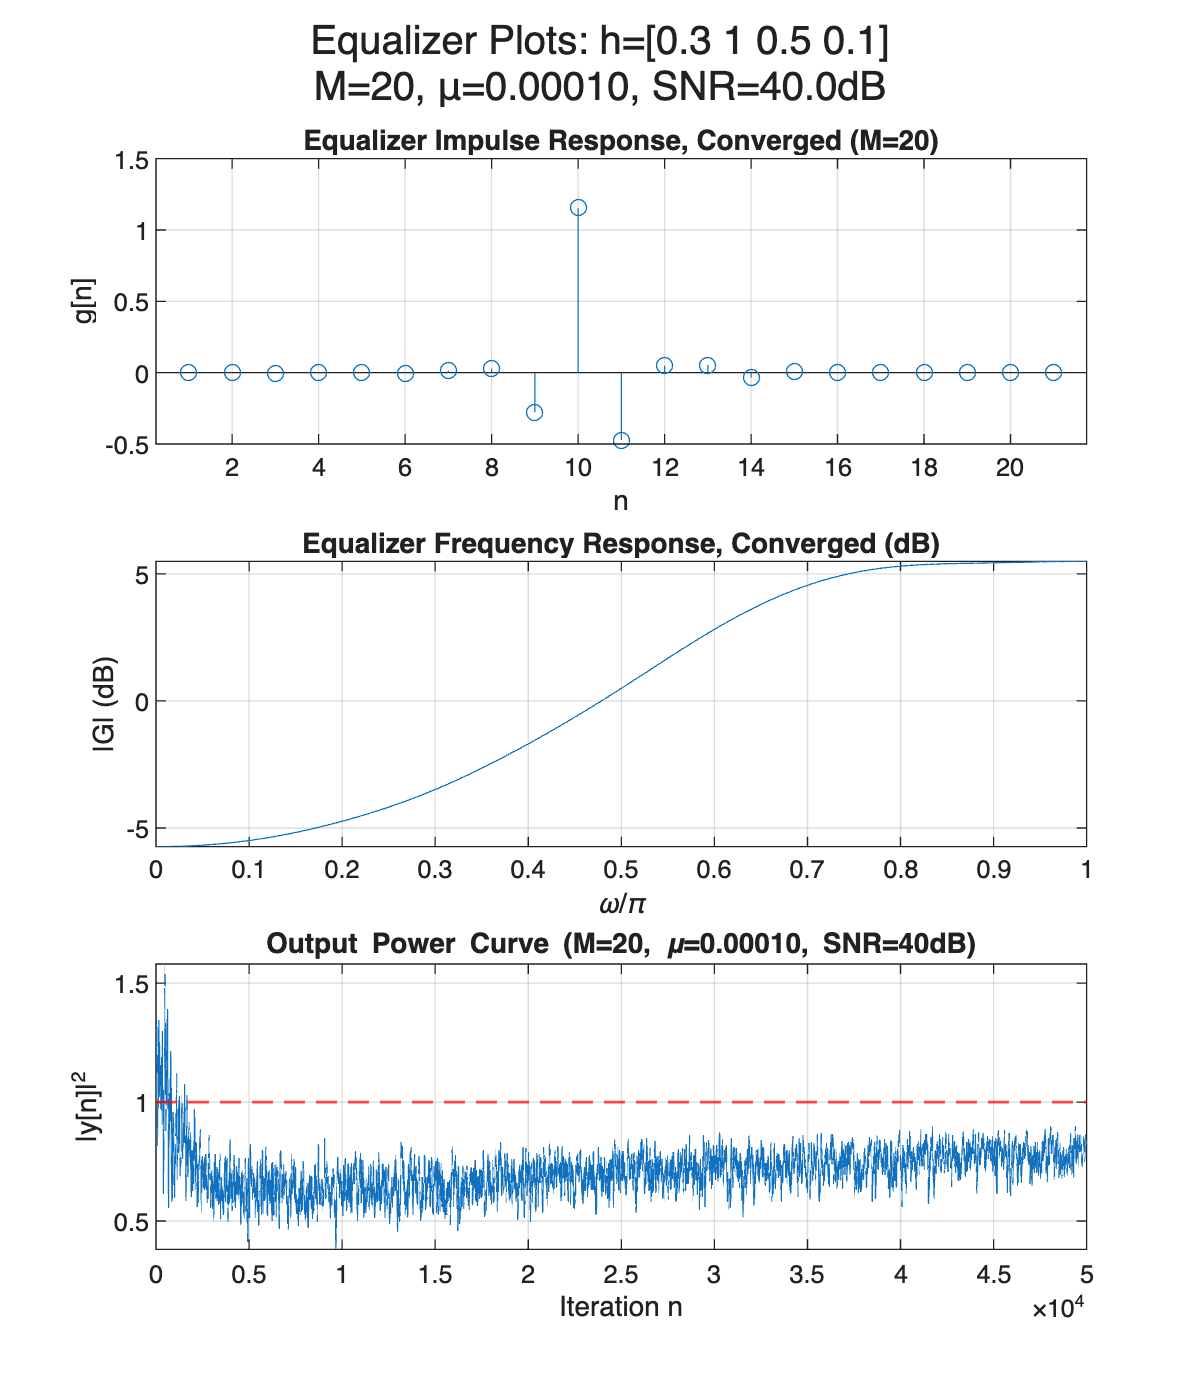


[gn_c, ~, yn_c, ~, ~] = run_blind_equalizer(h, mu, M, snr_db, 50000, "centered impulse");

plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);

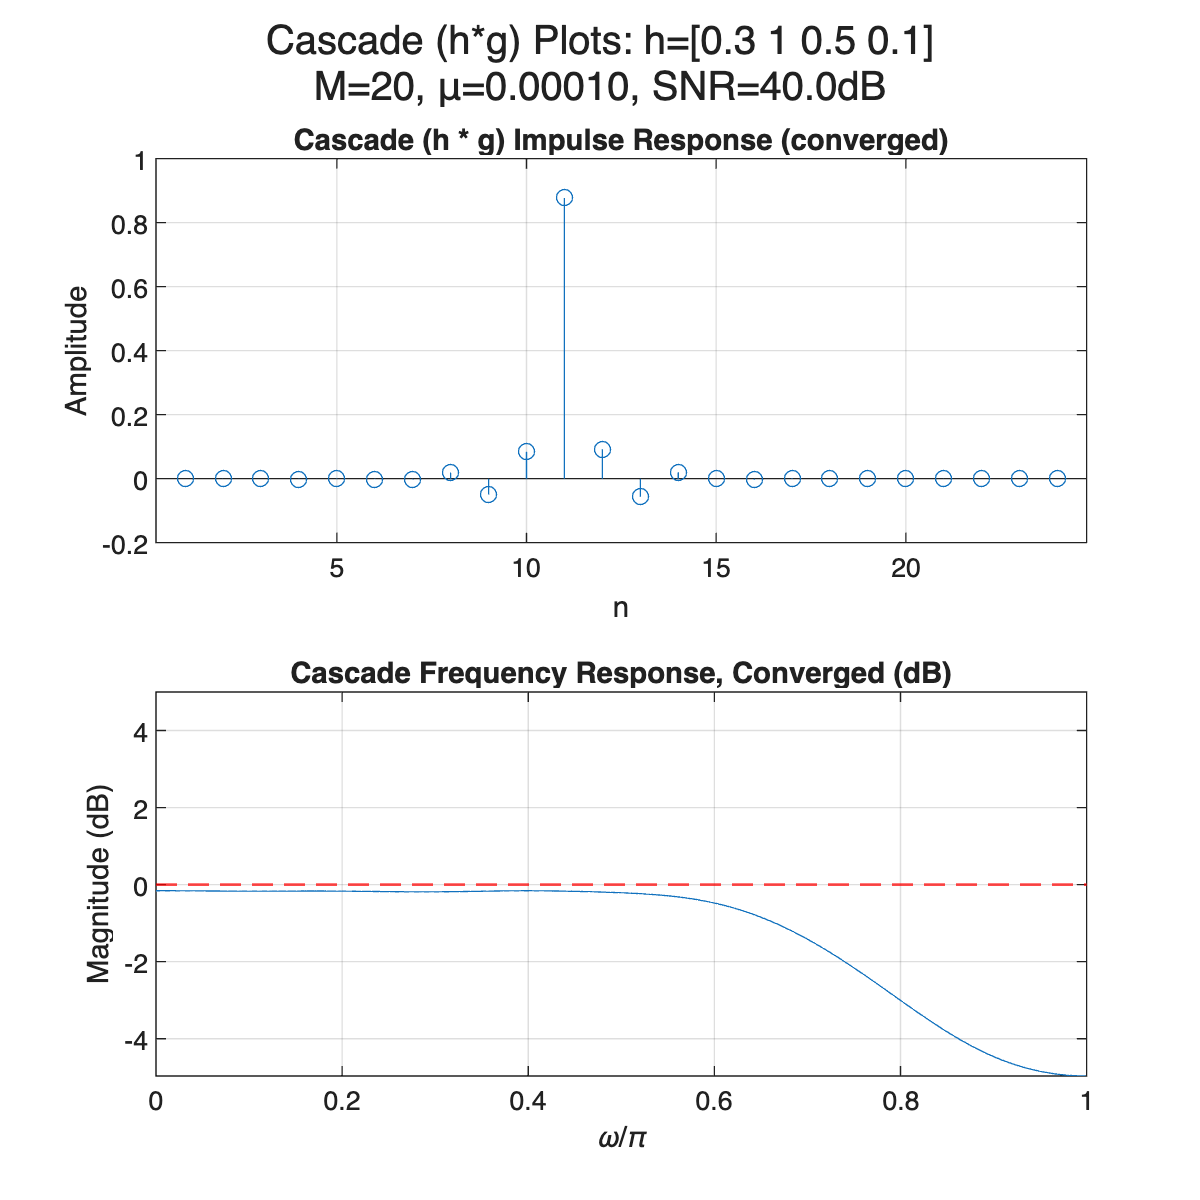

plot_cascade(h, gn_c, snr_db, mu, M);

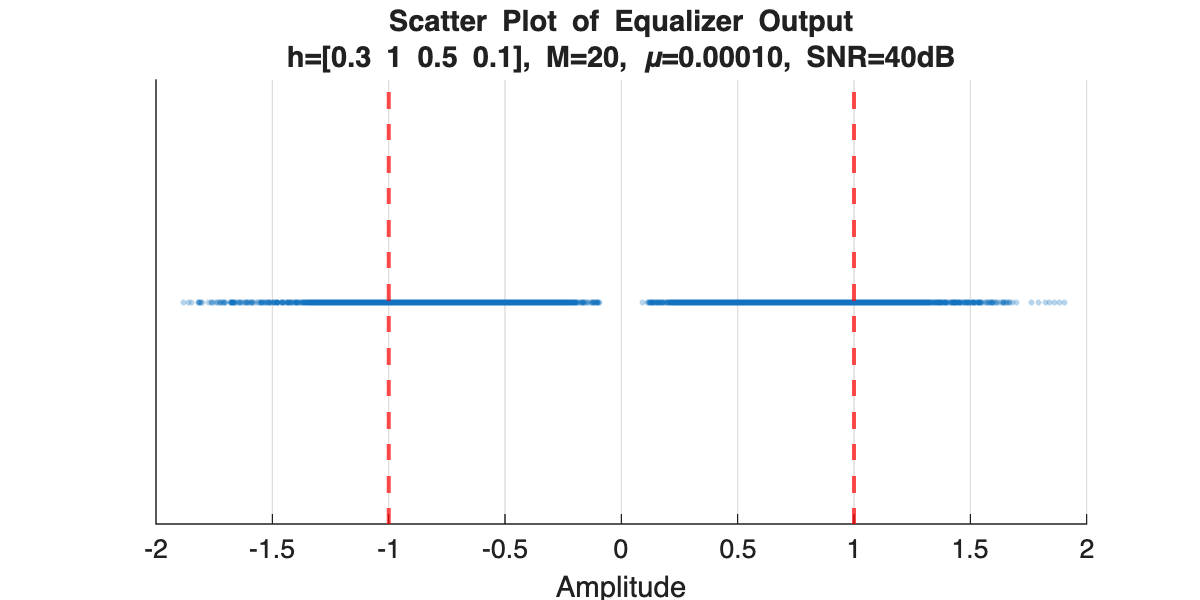

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 7 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 7 (SNR=40dB, M=20, mu=0.00010)


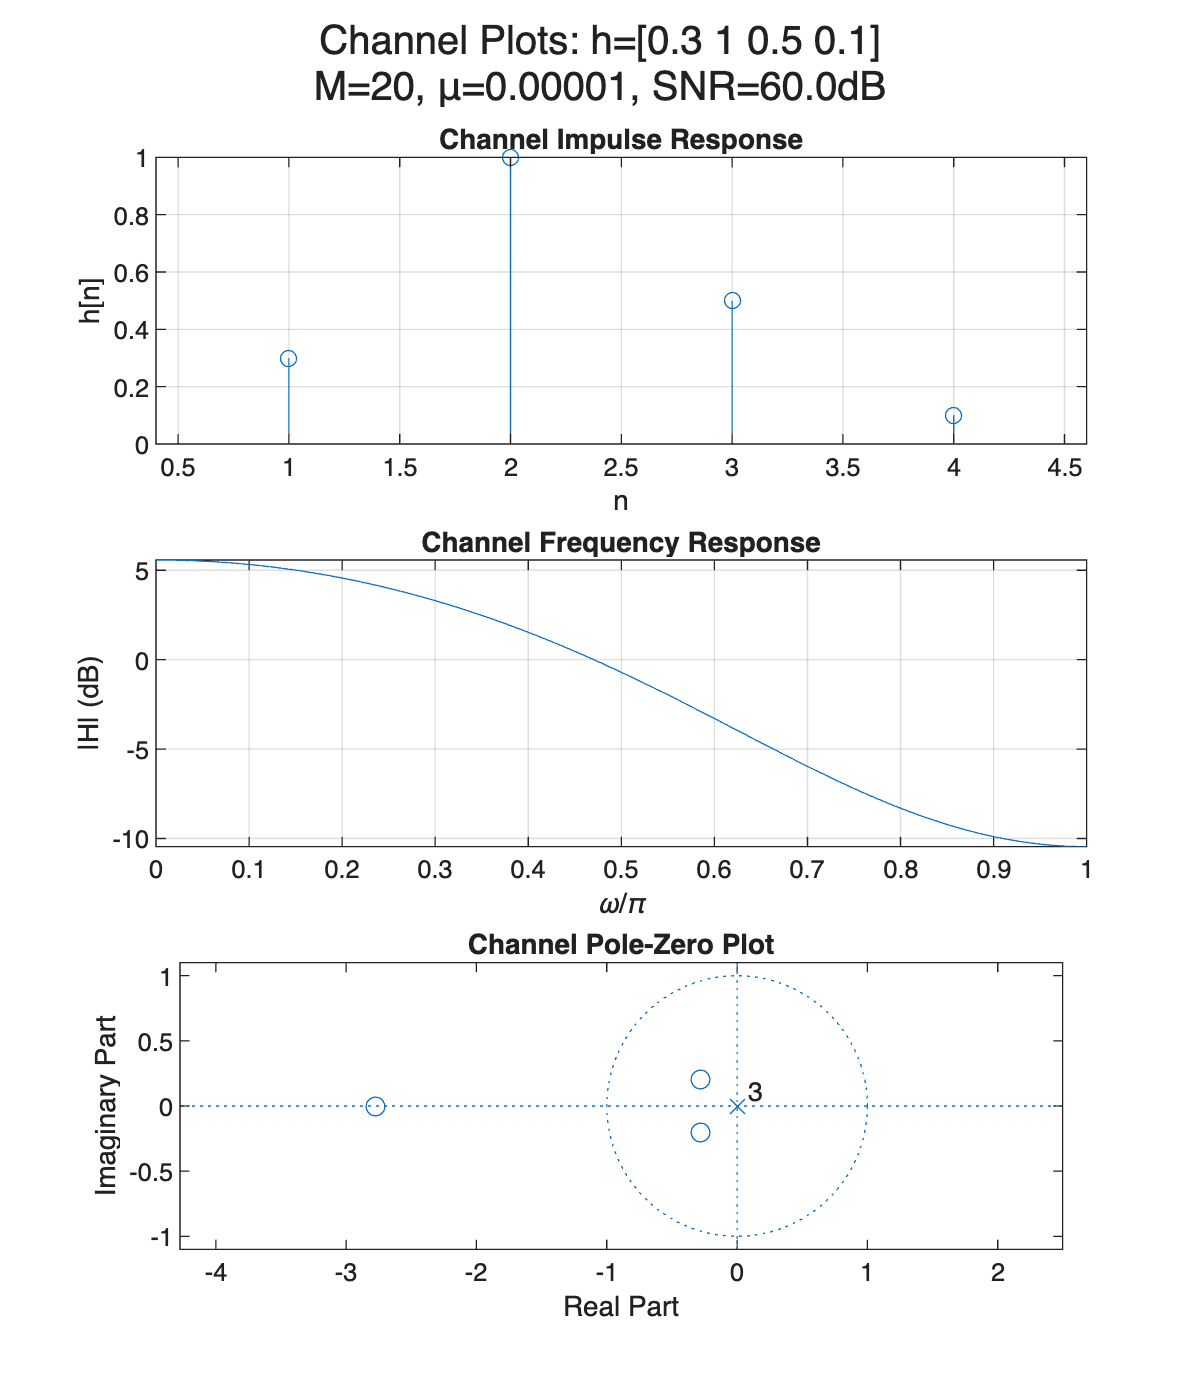

% TEST
snr_db = 60;
h = [0.3, 1, 0.5, 0.1];  
mu = 0.00001;
M = 20;

plot_channel(h, snr_db, mu, M);

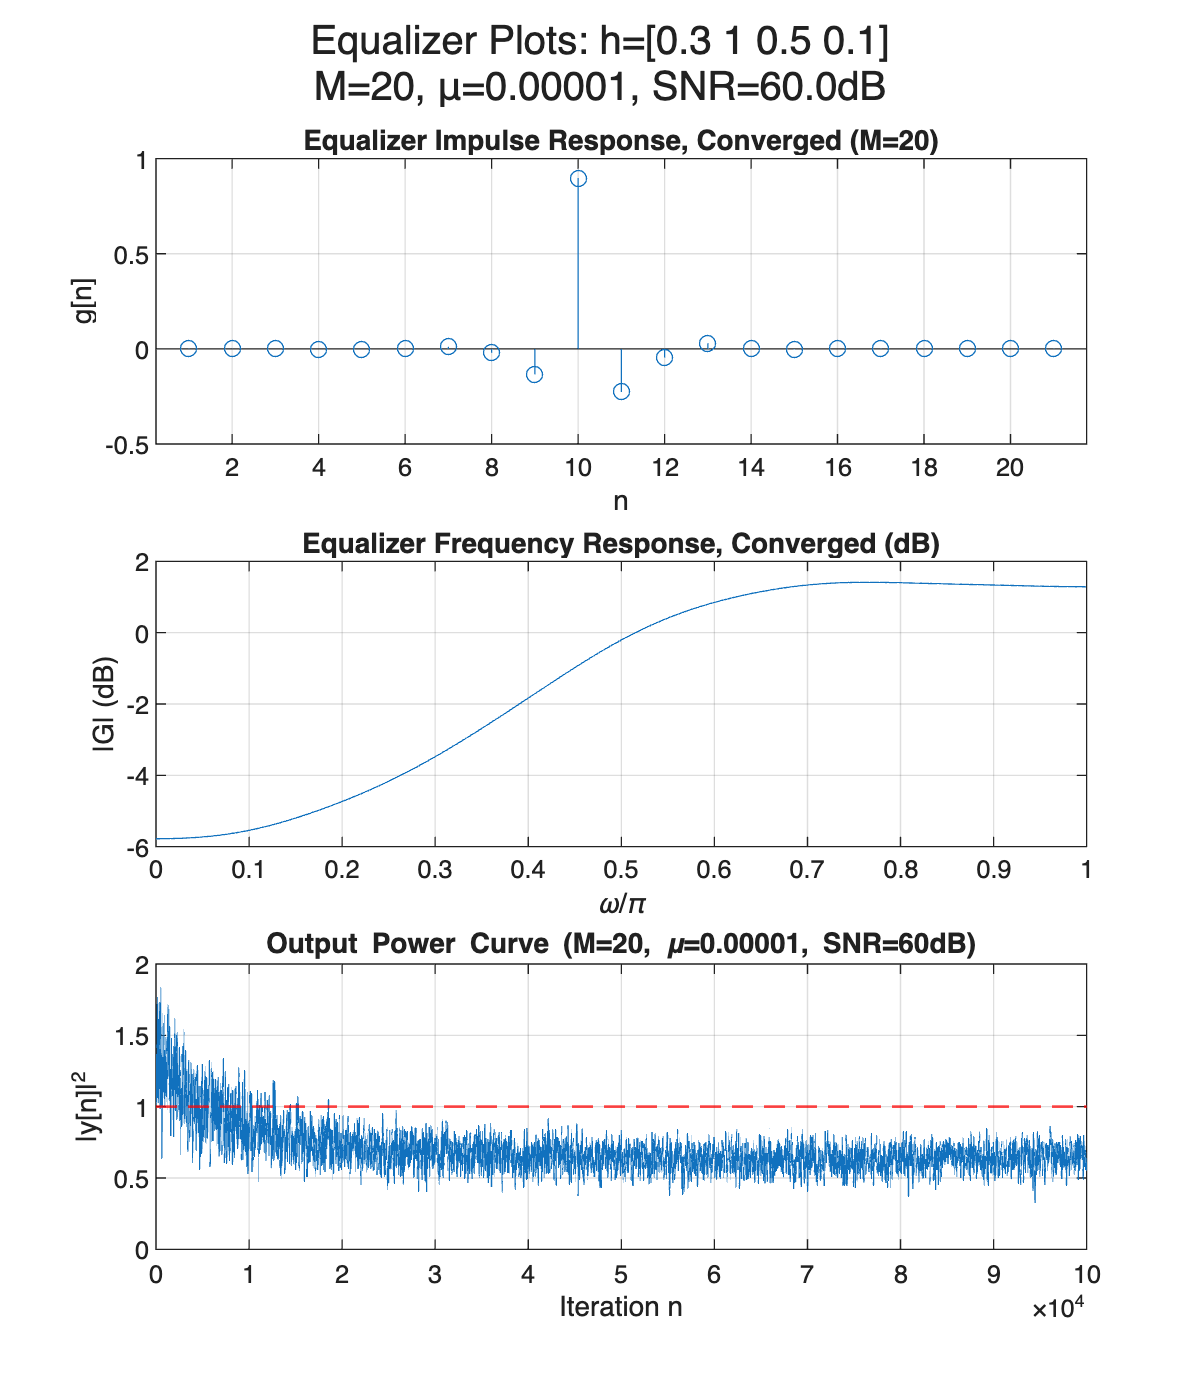


[gn_c, ~, yn_c, ~, ~] = run_blind_equalizer(h, mu, M, snr_db, 100000, "centered impulse");

plot_equalizer(h, gn_c, yn_c, snr_db, mu, M, window);

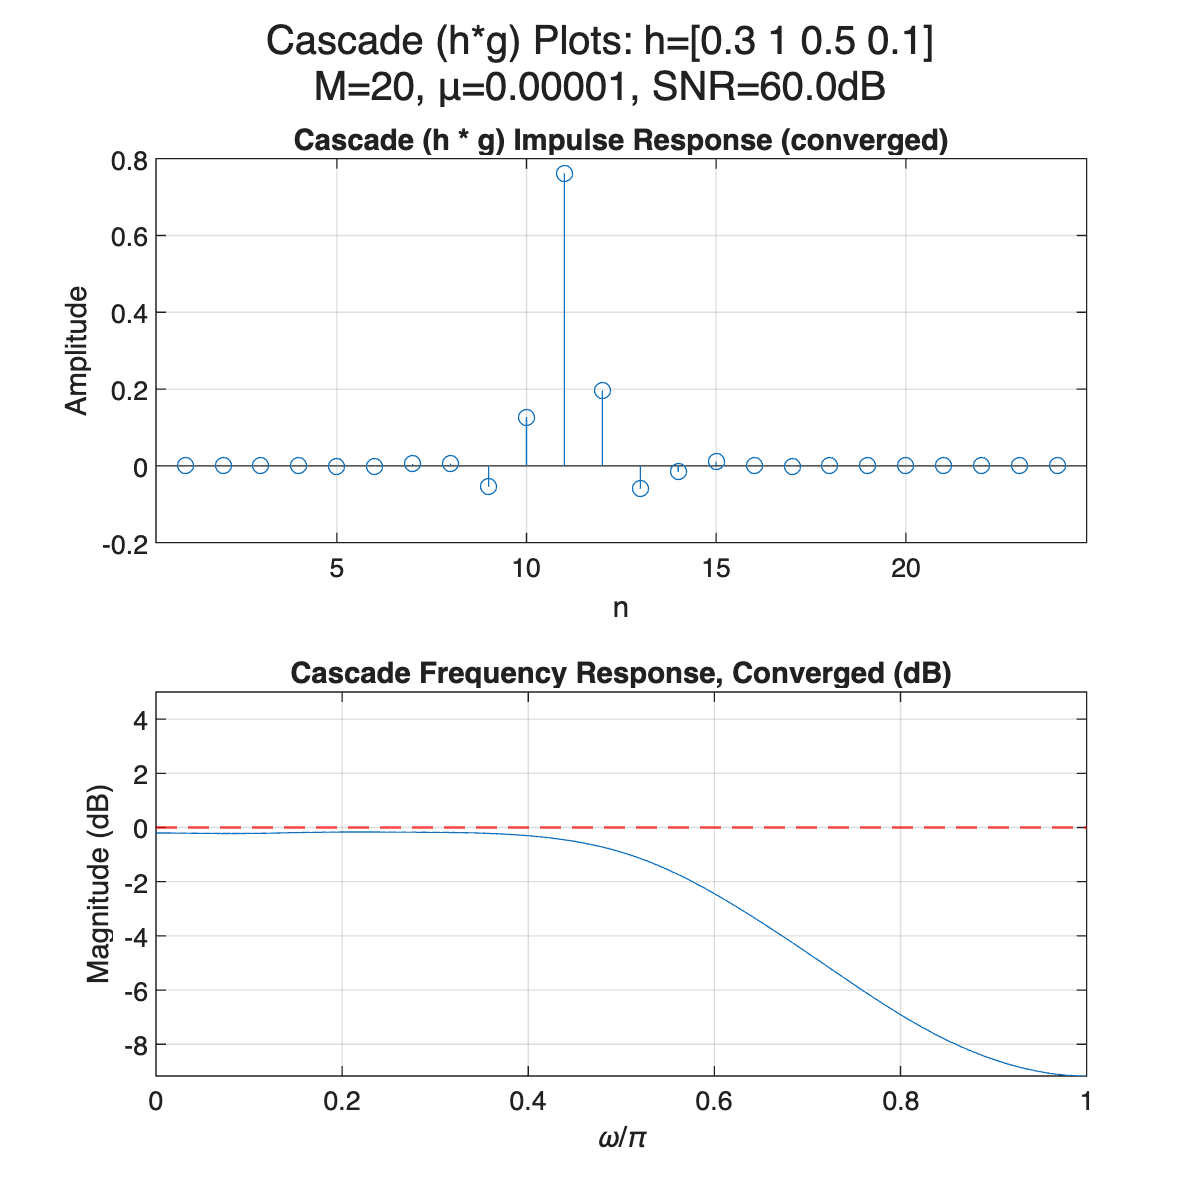

plot_cascade(h, gn_c, snr_db, mu, M);

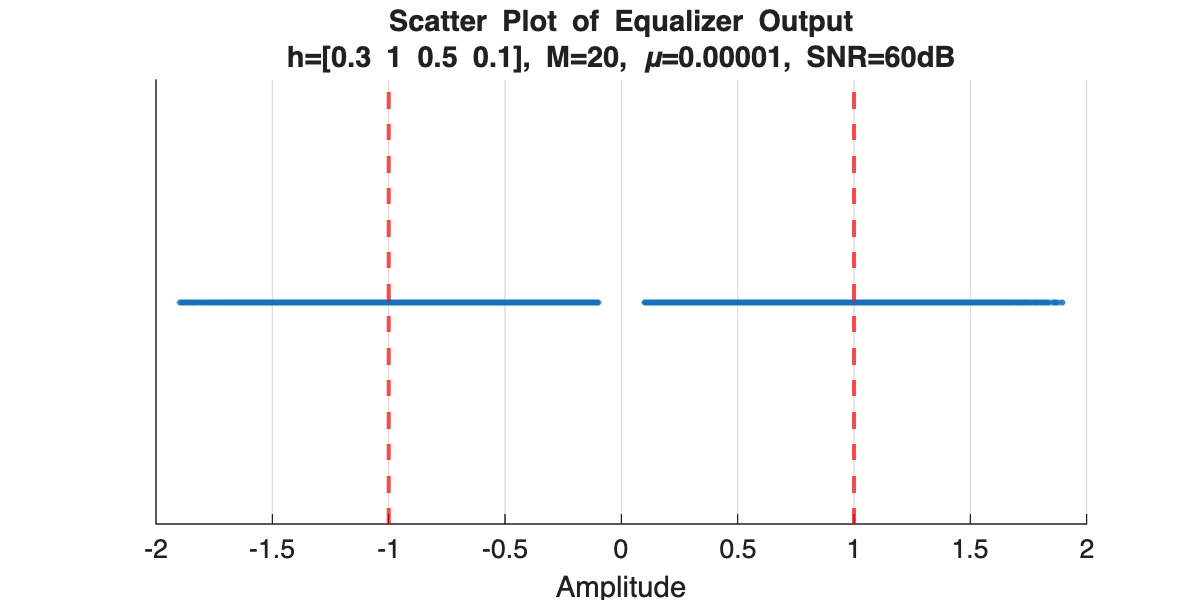

plot_scatter(yn_c, M, mu, snr_db, h);


fprintf('Blind Test 8 (SNR=%ddB, M=%d, mu=%.5f)\n', snr_db, M, mu);

Blind Test 8 (SNR=60dB, M=20, mu=0.00001)
